# Project 1

## Preprocessing

clear global

% Reading in the Excel file as a table then converting it into a matrix
mytable = readtable('project8_data.xlsx');
x = mytable{2:3,13:end};
x = transpose(x);

% 1st column: cumulative number of detected infections
V = x(:,1)
% 2nd column: Covid-19 related deaths reported in that specific county/city
Y = x(:,2)

Nmax = 236842; % Max population; from Population column
Tmax = 119;    % Number of days we will attempt to model
Tmaxnew = 40;  % Tmax cut in third
Vmin = 5;      % See below
tau0 = 7;      % Time between infection and full symptom onset
h = 0.01;      % Step size

% Sets used in omega set generation 
alphaSet = 0.05:0.01:0.2;
R0Set = 1.5:0.1:1.9;
deltaSet = 0.05:0.01:0.4;
NfracSet = 0.02:0.01:0.1;

% Norm used in error calculation
pSet = [1 2 inf];
pLen = length(pSet);

% Get the first day where at least Vmin were detected as infected
for i = 1:length(V)
    if V(i) >= Vmin
        break
    end
end
t0 = i

t0 = 52


% Preprocess rate of infections
I = zeros(Tmax+1,1); % note that I(t) represents the value of I at t+1
for t=0:Tmax
    I(t+1) = V(t+t0+tau0) - V(t+t0-tau0);
end
I

I =     17
    22
    26
    34
    35
    45
    52
    58
    68
    77



I0 = I(1)

I0 = 17

## Question 1

% Get parameters
% Function defined in generateParams1.m
[~, ~, ~, omega1] = generateParams1(alphaSet, R0Set, NfracSet, Nmax);
size(omega1)

ans =     16     5     9     3


% gammas(alphaInd, betaInd, NInd, p) contains 
% gamma as calculated to minimize p-norm of residual
% of actual results as compared to euler model 
% with given parameters (alpha, beta, N)
% J(...) contains the minimized function value
[J1, gammas1] = SIR_euler_allParams(t0, Tmax, I0, Y, I, omega1, pSet);

alphas iterated over: 0.05, 0.06, 0.07, 0.08, 0.09, 0.10, 0.11, 0.12, 0.13, 0.14, 0.15, 0.16, 0.17, 0.18, 0.19, 0.20, 

[~, ~, ~, paramMinp] = SIR_euler_minParams(omega1, pSet, J1, gammas1, Nmax)

For p = 1, the parameters which reduce the error are
For p = 2, the parameters which reduce the error are
For p = Inf, the parameters which reduce the error are


paramMinp = 3×4 cell array
    {[0.1100]}    {[0.2090]}    {[0.0367]}    {[4.7368e+03]}
    {[0.1100]}    {[0.2090]}    {[0.0362]}    {[4.7368e+03]}
    {[0.1100]}    {[0.2090]}    {[0.0345]}    {[4.7368e+03]}


TODO: 

- get R0, Nfrac, etc., interpret

- Compare R0 to the equation on slide 14 of [https://www.math.umd.edu/~rvbalan/TEACHING/MATH420Spring2023/LECTURES/Epi02_SIR.pdf](https://www.math.umd.edu/~rvbalan/TEACHING/MATH420Spring2023/LECTURES/Epi02_SIR.pdf) (see herd immunity matching expected from medical theory)

- Compare the number of susceptible population remaining (1 - ... count at 120), to N minus cumulative count...

- Use the same method on the validation set, do validation of our model 

- Compare output for Exercise 1 and Exercise 2 (directly)

- Use a different section of the data (e.g. middle third)

-     e.g. set the initial R value to the cumulative infected from 7 days before the start date of data, or derive it from gamma 

-     Note: it would be easy to optimize over R(0) because it doesn't affect the shape of the Euler sim output, only the vertical offset; so you could optimize it in the same place you optimize gamma

- We iterate over parameter to determine N, derive I from the data start, can estimate E the same way as R

Maybe later:

- Optimize over initial values for Ssim(1), Isim(1), Esim(1) -- keeping alpha and delta fixed (based on available medical information, i.e. using 7 days for infection period and 2-3 days for incubation period; alpha = 1/7, delta = 1/3)

-     Fix alpha, delta, let initial value for population (I0) differ

fig =   Figure (31) with properties:

      Number: 31
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


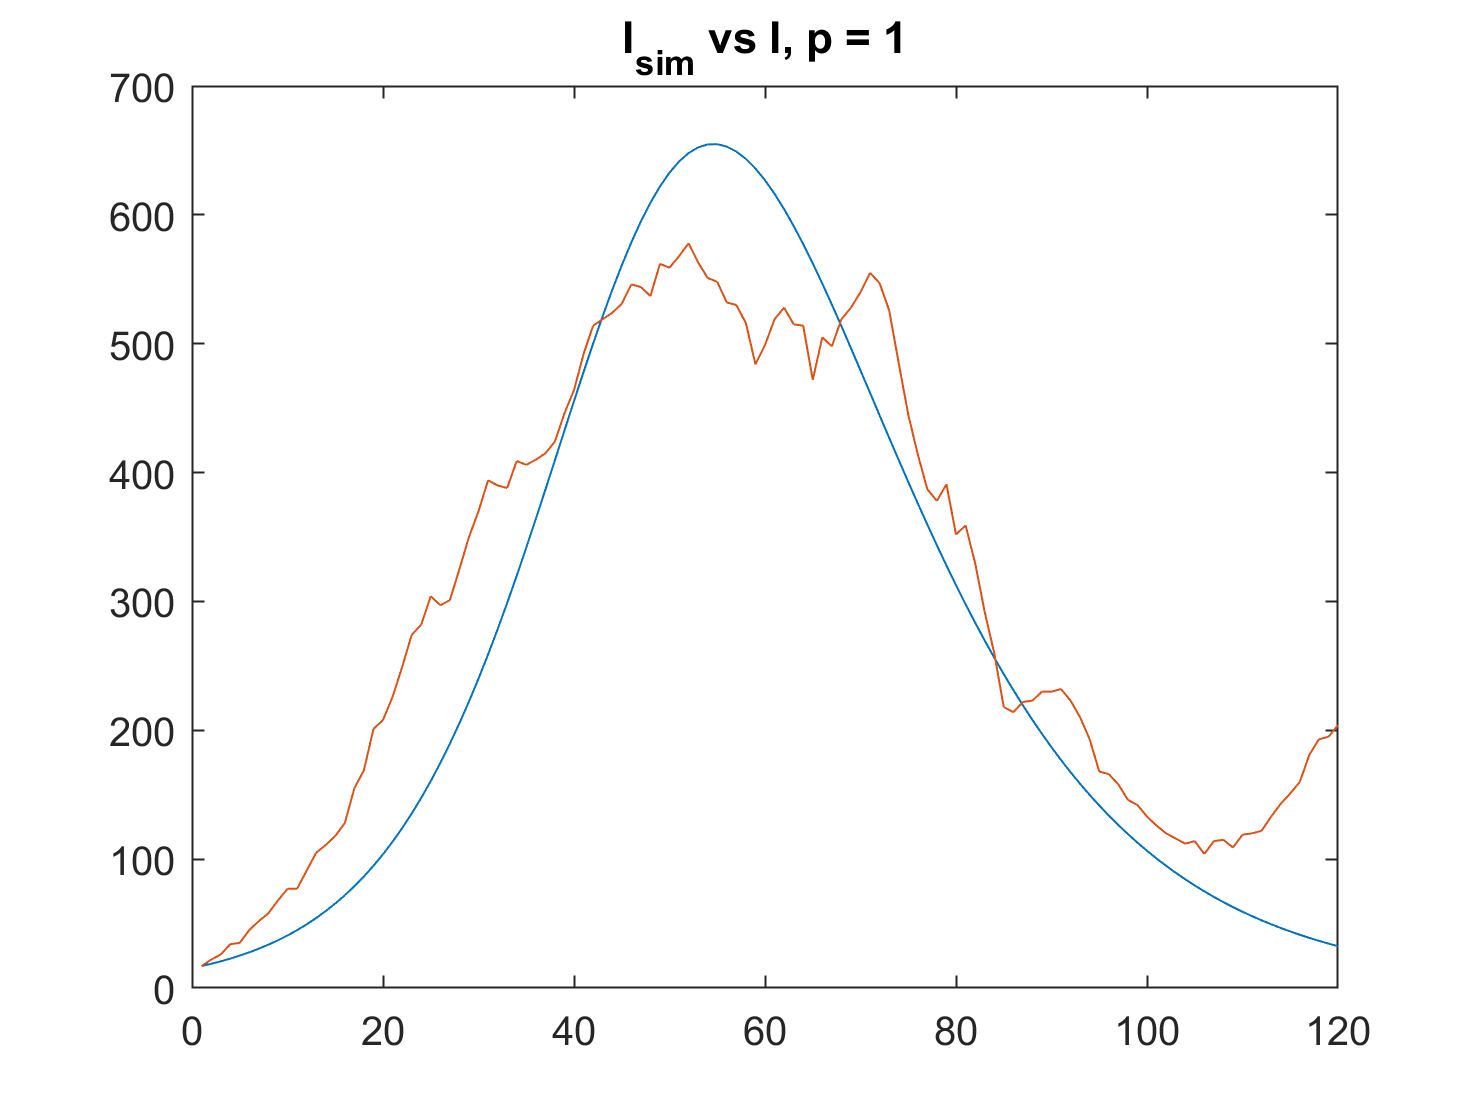

Error using saveas (line 138)
Invalid or missing path: VA_SIR/VA_SIR_p_1_I.png

%figure
%tl = tiledlayout('flow');
for pInd = 1:pLen
    p = pSet(pInd);
    % Get minimum parameter values
    paramMin = paramMinp(pInd,:);
    [alphaMin, betaMin, gammaMin, NMin] = paramMin{:};

    % Recalculated because it's not stored previously
    [Ssim, Isim, Rsim] = SIR_euler(I0, Tmax, alphaMin, betaMin, NMin);

    % Compare Isim and I
    %nexttile
    fig = figure
    plot(Isim)
    hold on
    plot(I)
    hold off
    %legend(["predicted", "actual"])
    title(['I_{sim} vs I, p = ', num2str(p)])

    saveas(fig, sprintf("VA_SIR/VA_SIR_p_%d_I.png",p))

    % Compare Y and Ysim = gamma * Rsim
    %nexttile
    fig = figure
    plot(gammaMin * Rsim)
    hold on
    plot(Y(t0:t0+Tmax))
    hold off
    %legend(["predicted", "actual"])
    title(['Y_{sim} vs Y, p = ', num2str(p)])

    saveas(fig, sprintf("VA_SIR/VA_SIR_p_%d_Y.png",p))

    % Find value of Isim after index t0 below Vmin
    % TODO should I be looking at V instead? I don't know
    % how I would compare that with the output of the model...
    temp_mat = (Isim(t0+1:end)<=Vmin);
    %temp_mat(temp_mat == 0) = NaN;
    [~, min_idx] = max(temp_mat);
end

## Question 2

[J2, gammas2] = SIR_euler_allParams(t0, Tmaxnew, I0, Y, I, omega1, pSet);

alphas iterated over: 0.05, 0.06, 0.07, 0.08, 0.09, 0.10, 0.11, 0.12, 0.13, 0.14, 0.15, 0.16, 0.17, 0.18, 0.19, 0.20, 


[~, ~, ~, paramMinp2] = SIR_euler_minParams(omega1, pSet, J2, gammas2)

For p = 1, the parameters which reduce the error are
For p = 2, the parameters which reduce the error are
For p = Inf, the parameters which reduce the error are


paramMinp2 = 3×4 cell array
    {[0.1900]}    {[0.3230]}    {[0.0103]}    {[4.7368e+03]}
    {[0.1900]}    {[0.3230]}    {[0.0097]}    {[4.7368e+03]}
    {[0.1800]}    {[0.3060]}    {[0.0103]}    {[4.7368e+03]}


Estimate if and when the infections would die down, i.e., when the number of infections would fall below Vmin = 5.

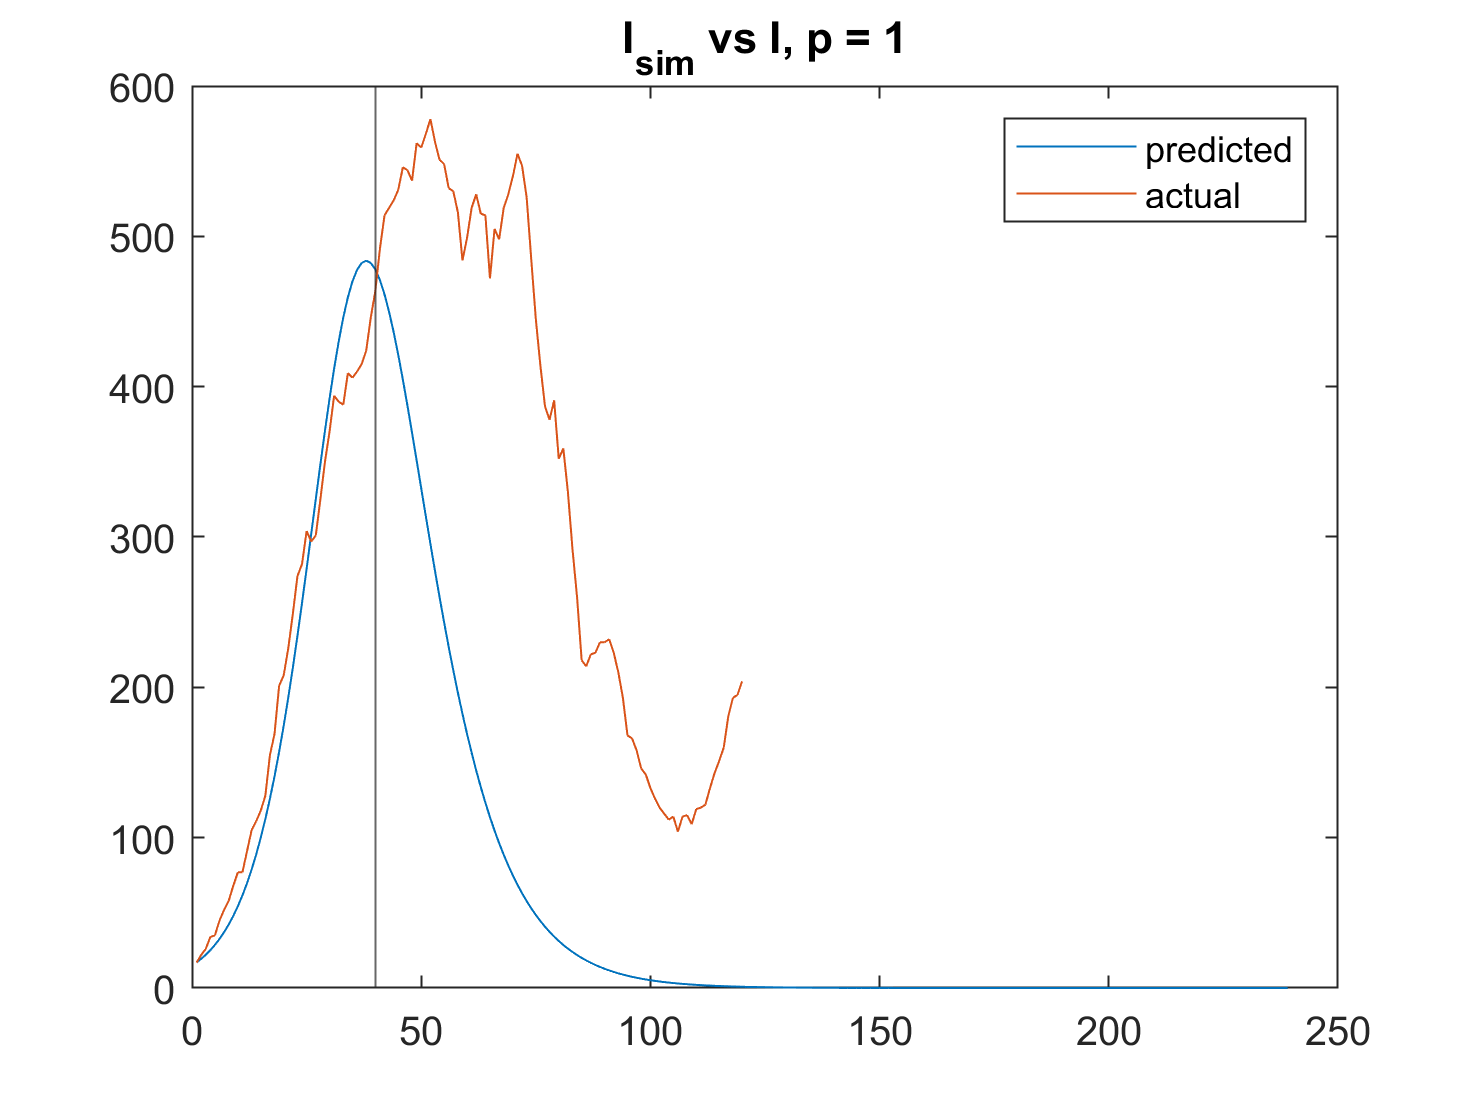

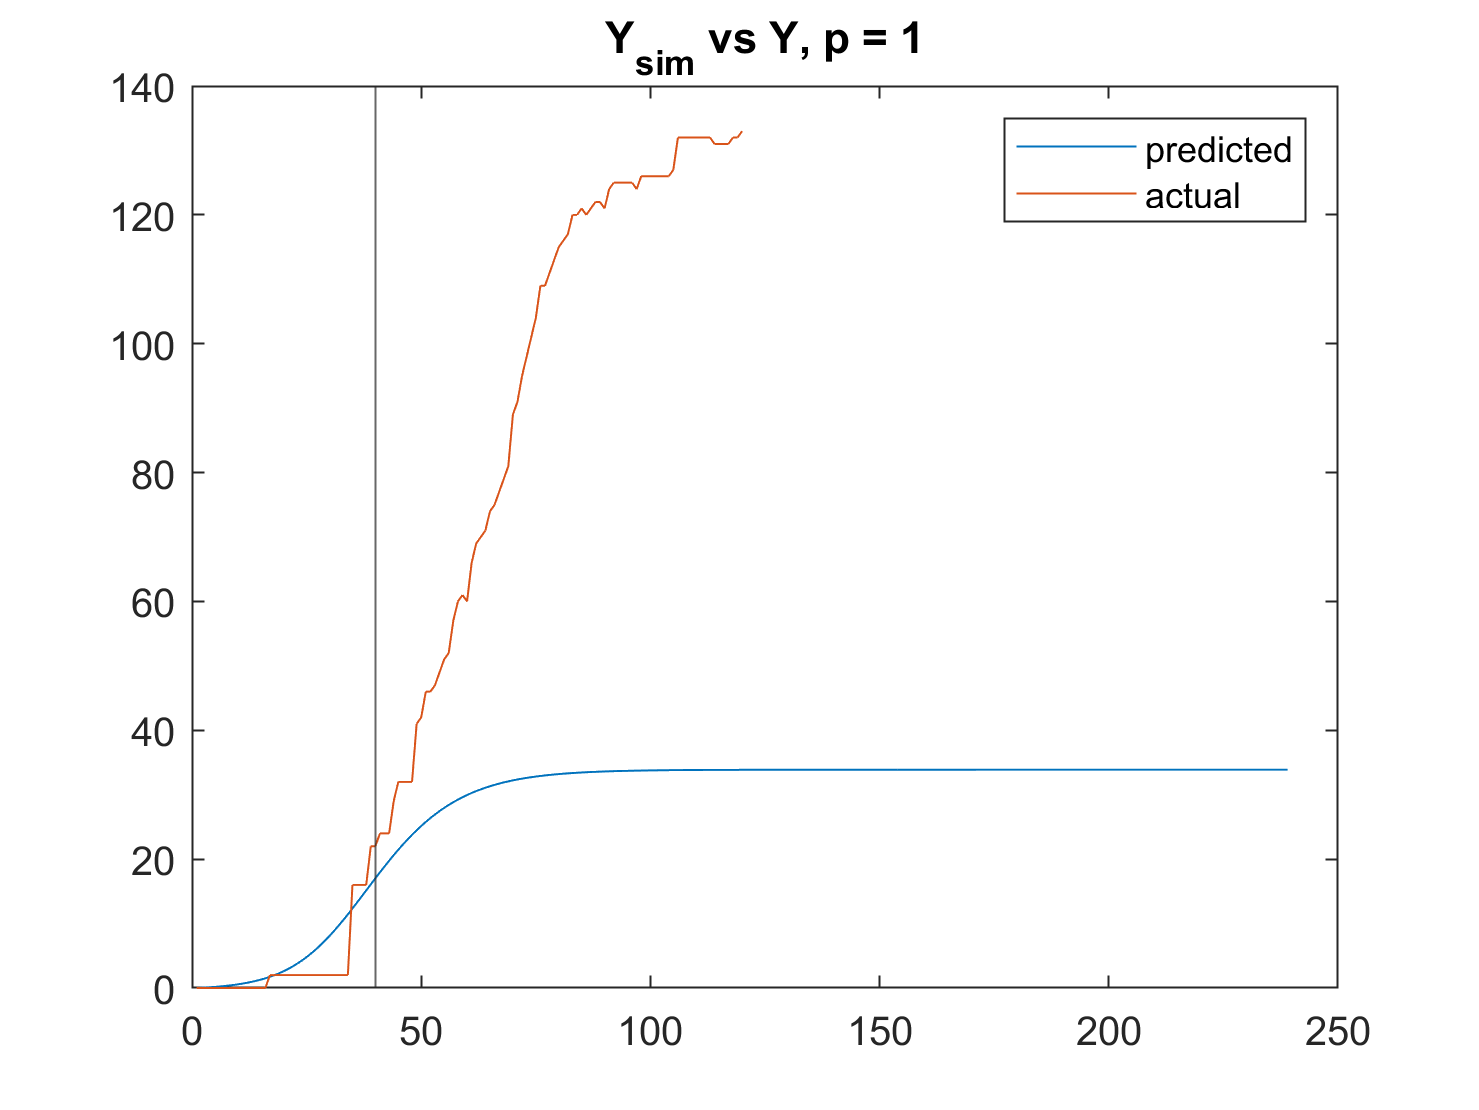

p = 1, predict first day below 5 infections after t0=52 is 101


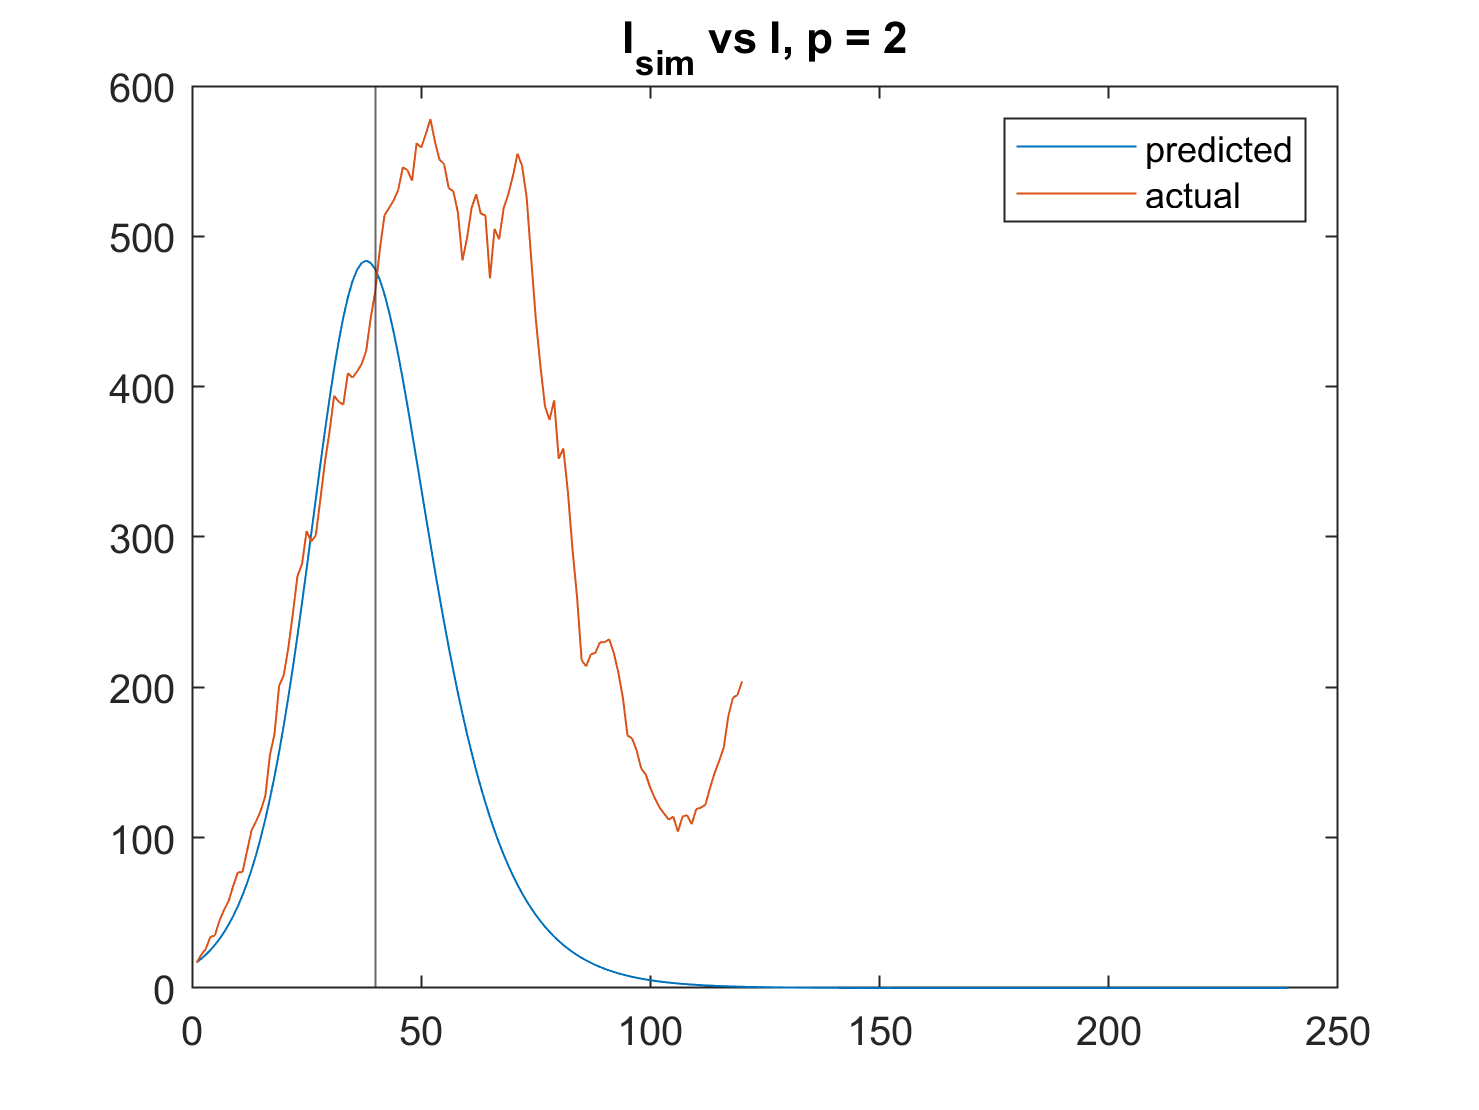

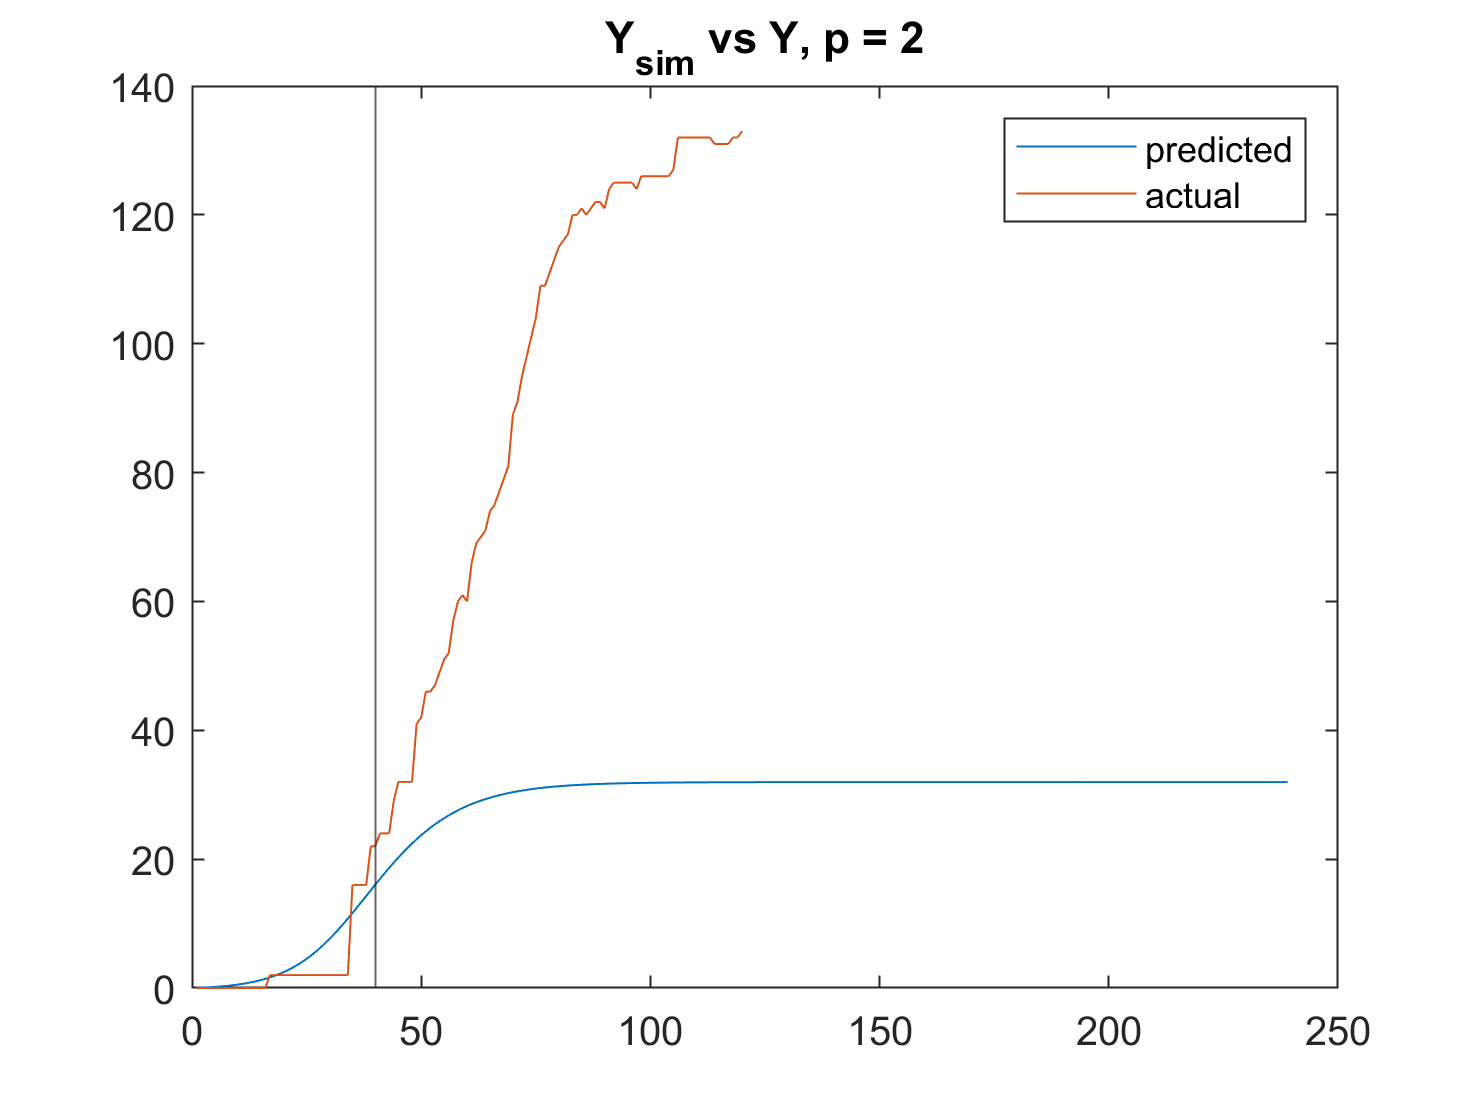

p = 2, predict first day below 5 infections after t0=52 is 101


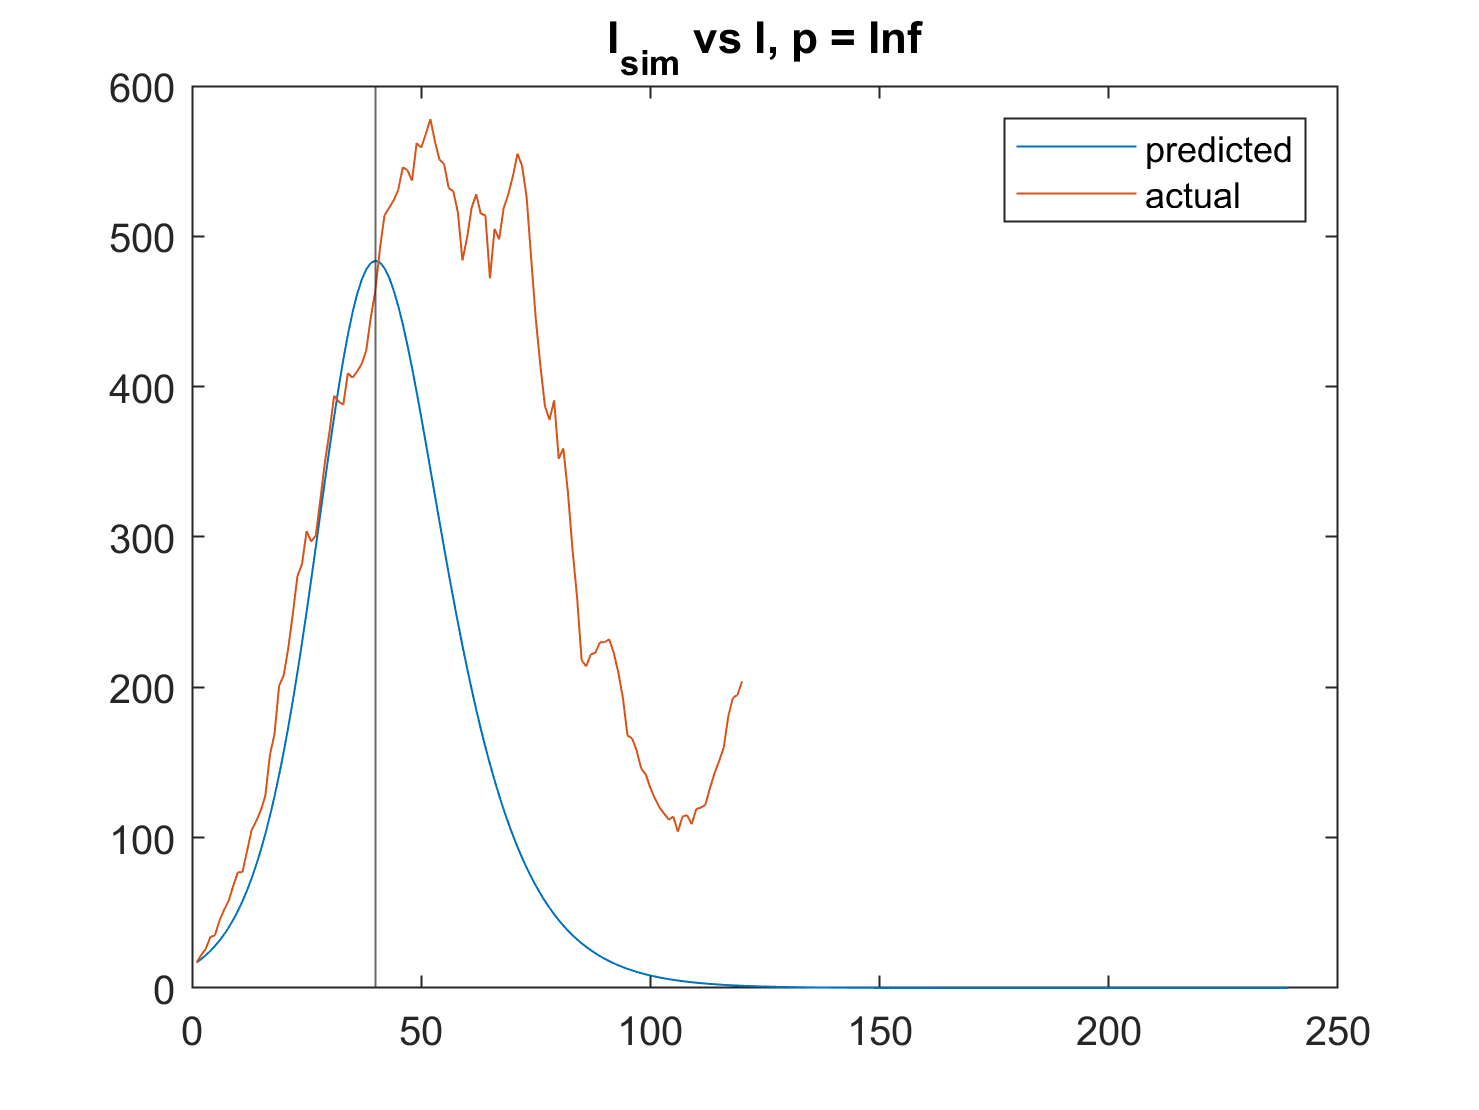

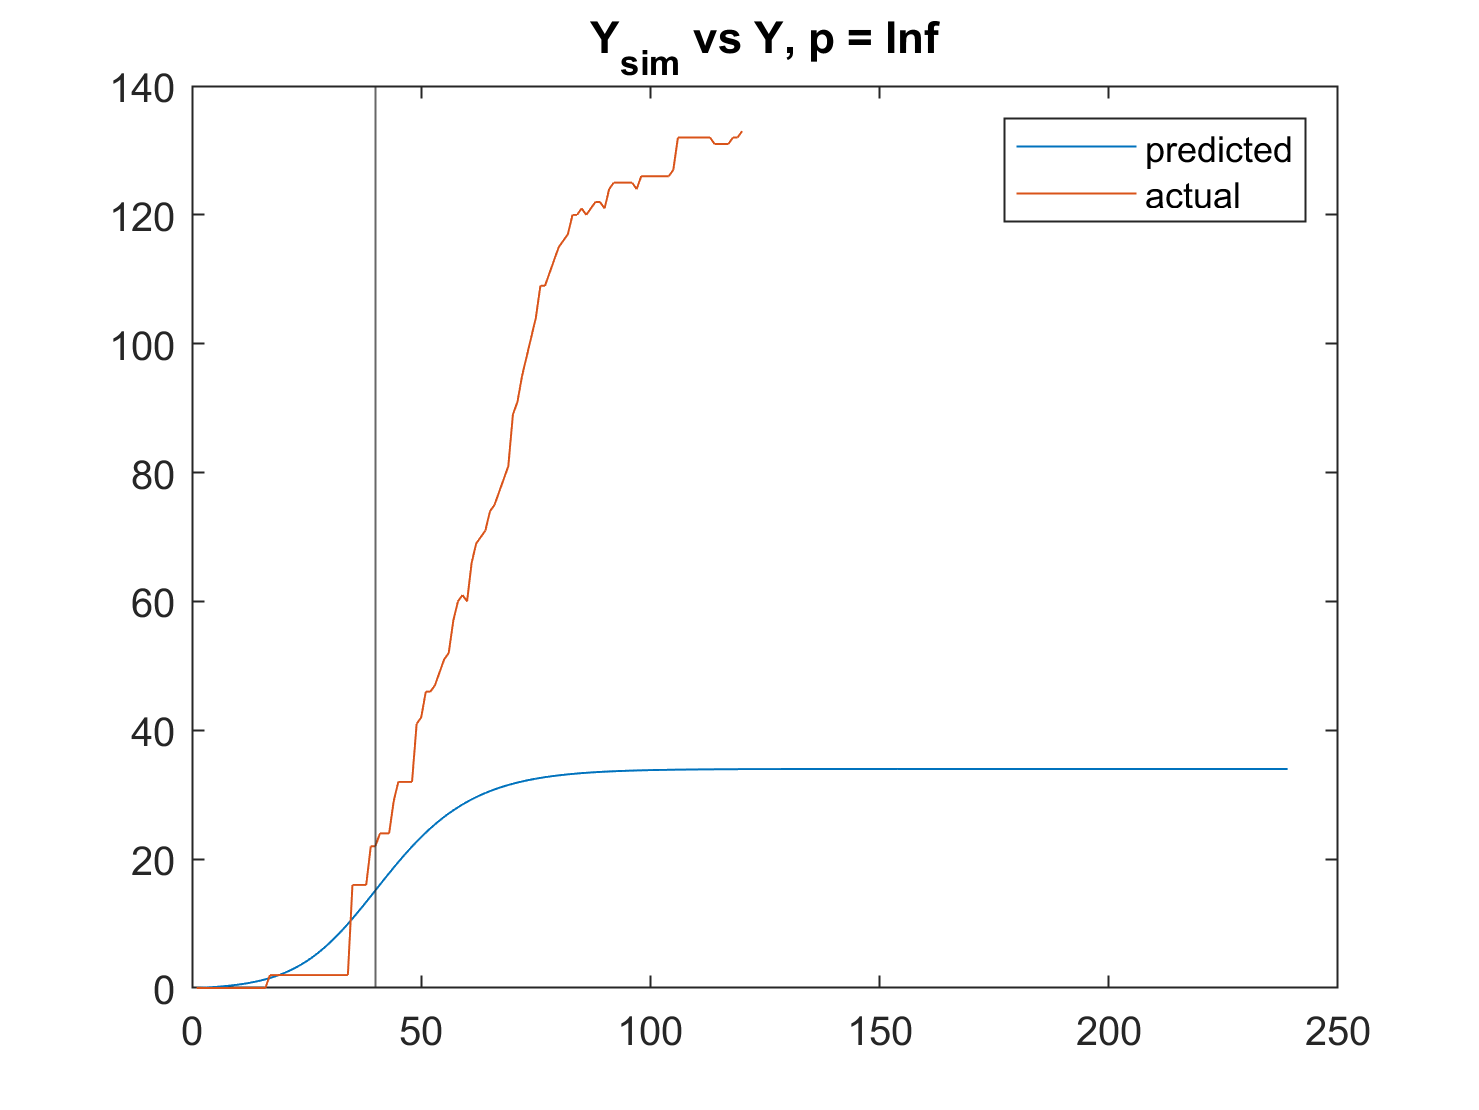

p = Inf, predict first day below 5 infections after t0=52 is 106


%figure
%tl = tiledlayout('flow');

for pInd = 1:pLen
    p = pSet(pInd);
    % Get minimum parameter values
    paramMin = paramMinp2(pInd,:);
    [alphaMin, betaMin, gammaMin, NMin] = paramMin{:};

    % Recalculated because it's not stored previously
    [Ssim, Isim, Rsim] = SIR_euler(I0, Tmax * 2, alphaMin, betaMin, NMin);

    % Compare Isim and I
    %nexttile
    figure
    plot(Isim)
    hold on
    plot(I)
    xline(Tmaxnew)
    hold off
    legend(["predicted", "actual"])
    title(['I_{sim} vs I, p = ', num2str(p)])

    saveas(fig, sprintf("VA_SIR/Prediction/VA_SIR_Prediction_p_%d_I.png",p))

    % Compare Y and Ysim = gamma * Rsim
    %nexttile
    figure
    plot(gammaMin * Rsim)
    hold on
    plot(Y(t0:t0+Tmax))
    xline(Tmaxnew)
    hold off
    legend(["predicted", "actual"])
    title(['Y_{sim} vs Y, p = ', num2str(p)])    

    saveas(fig, sprintf("VA_SIR/Prediction/VA_SIR_Prediction_p_%d_Y.png",p))

    % Find value of Isim after index t0 below Vmin
    % TODO should I be looking at V instead? I don't know
    % how I would compare that with the output of the model...
    temp_mat = (Isim(t0+1:end)<=Vmin);
    %temp_mat(temp_mat == 0) = NaN;
    [~, min_idx] = max(temp_mat);

    fprintf("p = %d, predict first day below %d infections after t0=%d is %d\n", ...
        p, Vmin, t0, min_idx+t0)
    fprintf("")
end


fprintf("In reality, within the given data, I never goes below %d after t0=%d.\n", Vmin, t0)

In reality, within the given data, I never goes below 5 after t0=52.


## Question 3

% Get parameters
% Function defined in generateParams2.m
[alphaLen, betaLen, deltaLen, NLen, omega2] = generateParams2(alphaSet, R0Set, deltaSet, NfracSet, Nmax);

Unrecognized function or variable 'alphaSet'.

% gammas(alphaInd, betaInd, deltaInd, NInd, p) contains 
% gamma as calculated to minimize p-norm of residual
% of actual results as compared to euler model 
% with given parameters (alpha, beta, delta, N)
% J(...) contains the minimized function value
%[J3, gammas3] = SEIR_euler_allParams(t0, Tmax, I0, Y, omega2, pSet);

% Save results (so if I need to restart I don't lose the calculations)
% Commented so that I don't overwrite the results later
%writematrix(J3,"project1_q3_errors_all_p.txt")
%writematrix(gammas3,"project1_q3_gammas_all_p.txt")

% Load matrix from file above
J3 = readmatrix("project1_q3_errors_all_p.txt");
J3 = reshape(J3, alphaLen, betaLen, deltaLen, NLen, pLen, 3)

Unrecognized function or variable 'alphaLen'.

gammas3 = readmatrix("project1_q3_gammas_all_p.txt")
gammas3 = reshape(gammas3, alphaLen, betaLen, deltaLen, NLen, pLen, [])
size(J3)
size(gammas3)

[~, ~, ~, ~, paramMinp3] = SEIR_euler_minParams(omega2, pSet, J3, gammas3, Nmax)

For p = 1, the parameters which reduce the error are
alpha = 0.190, beta = 0.059, gamma = 0.018, delta = 1.800, N = 9473.68
(R0 = 0.310, Nfrac = 0.040)
with an error of 284.188991

For p = 2, the parameters which reduce the error are
alpha = 0.200, beta = 0.058, gamma = 0.015, delta = 1.900, N = 11842.1
(R0 = 0.290, Nfrac = 0.050)
with an error of 34.398453

For p = Inf, the parameters which reduce the error are
alpha = 0.190, beta = 0.057, gamma = 0.012, delta = 1.900, N = 14210.5
(R0 = 0.300, Nfrac = 0.060)
with an error of 7.682027



paramMinp3 = 3×5 cell array
    {[0.1900]}    {[0.0589]}    {[0.0182]}    {[1.8000]}    {[9.4737e+03]}
    {[0.2000]}    {[0.0580]}    {[0.0152]}    {[1.9000]}    {[1.1842e+04]}
    {[0.1900]}    {[0.0570]}    {[0.0117]}    {[1.9000]}    {[1.4211e+04]}


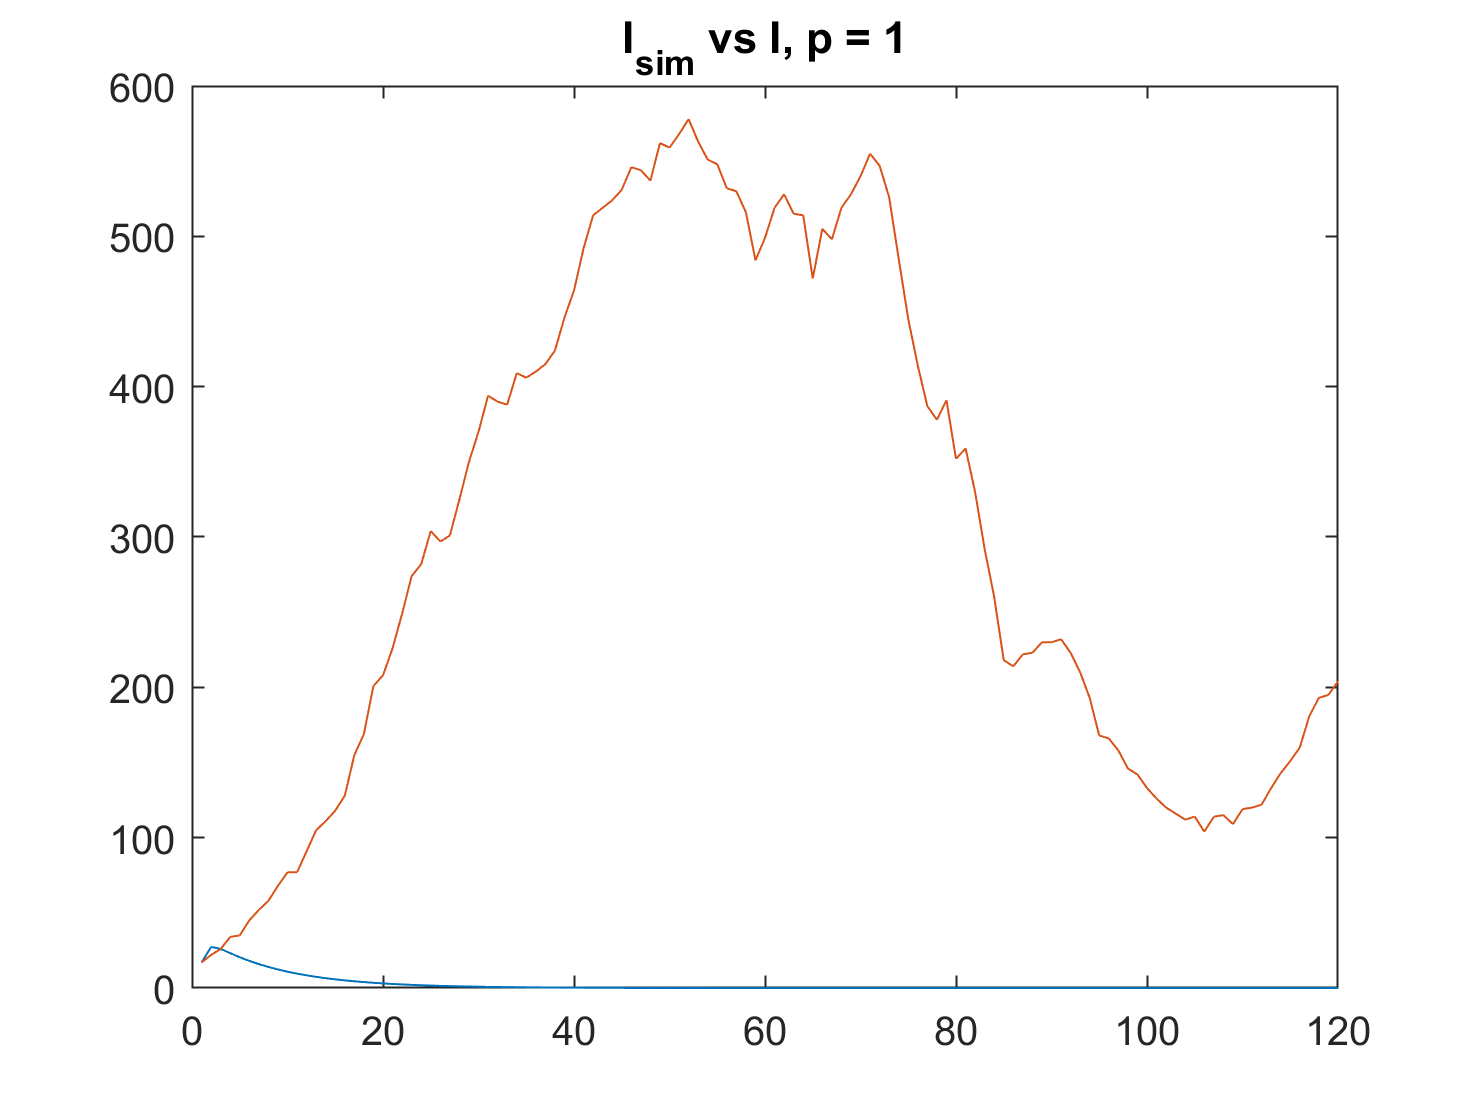

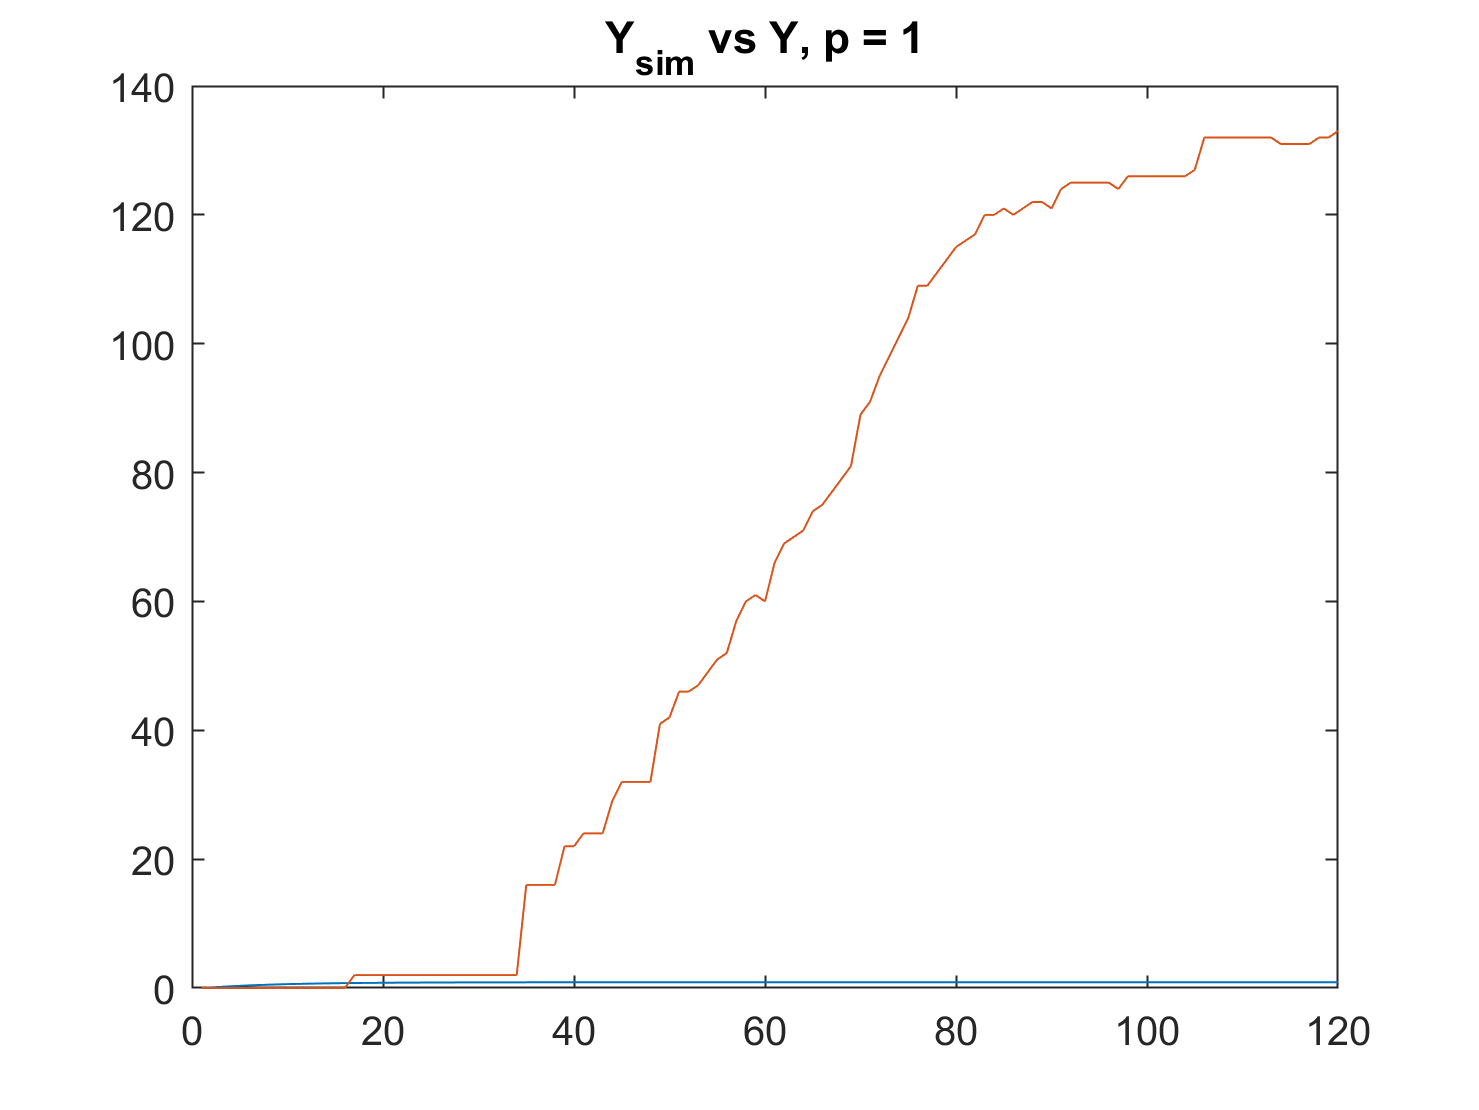

p = 1, predict first day below 5 infections after t0=52 is 53


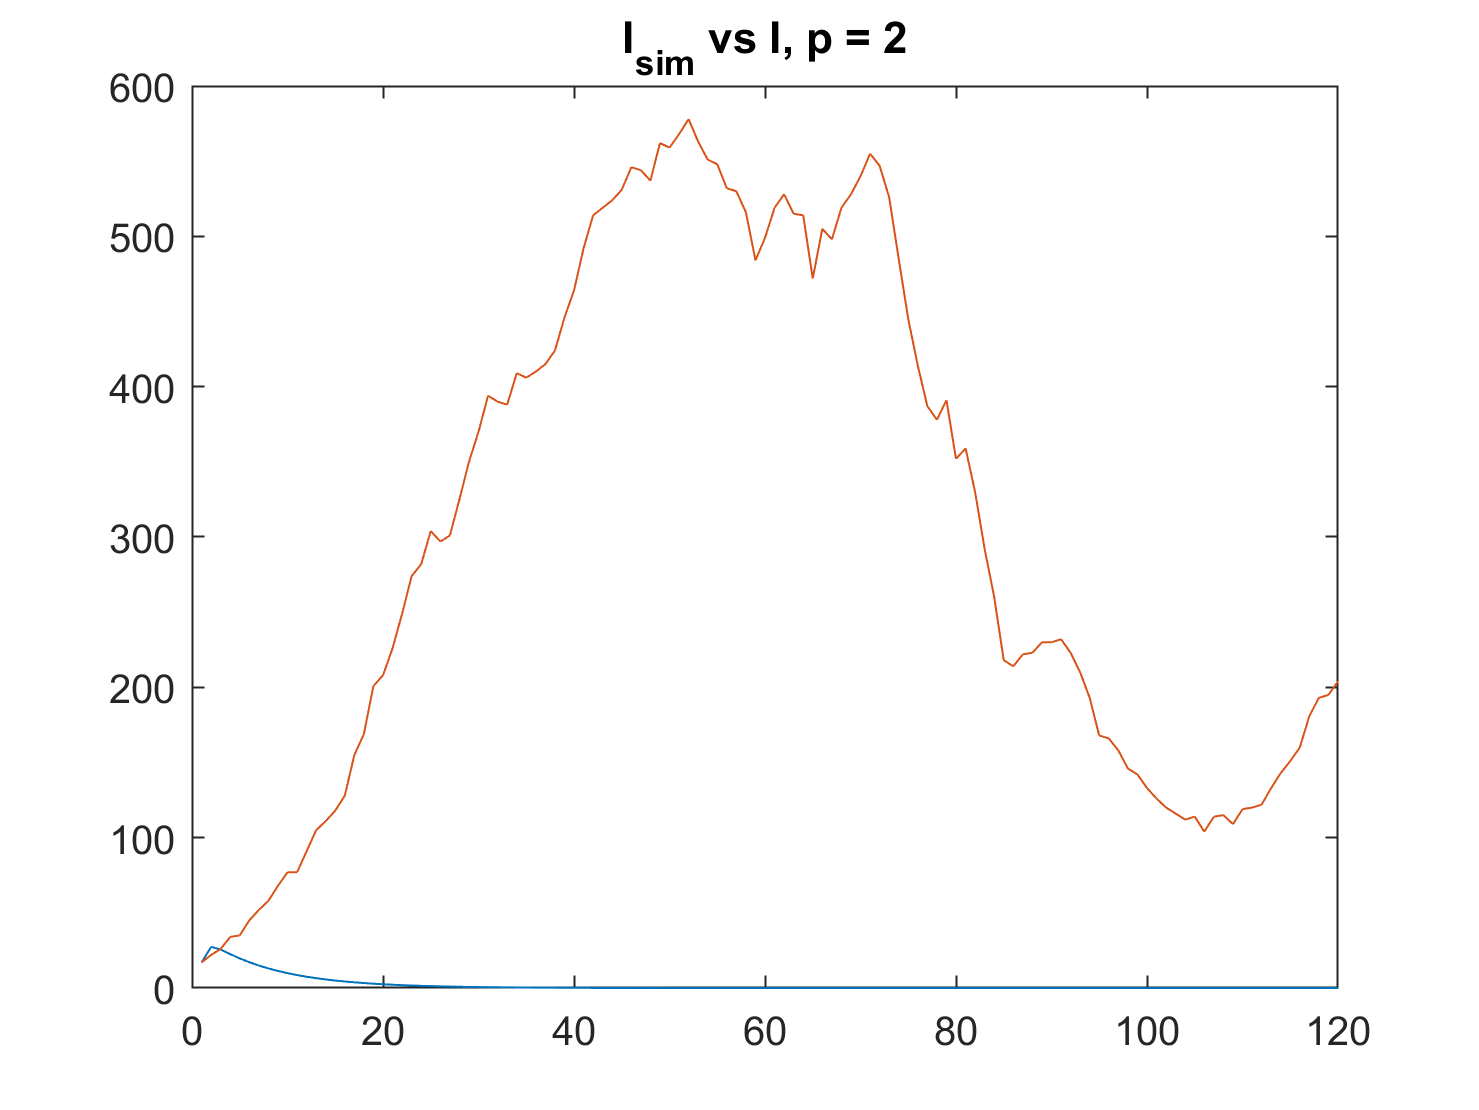

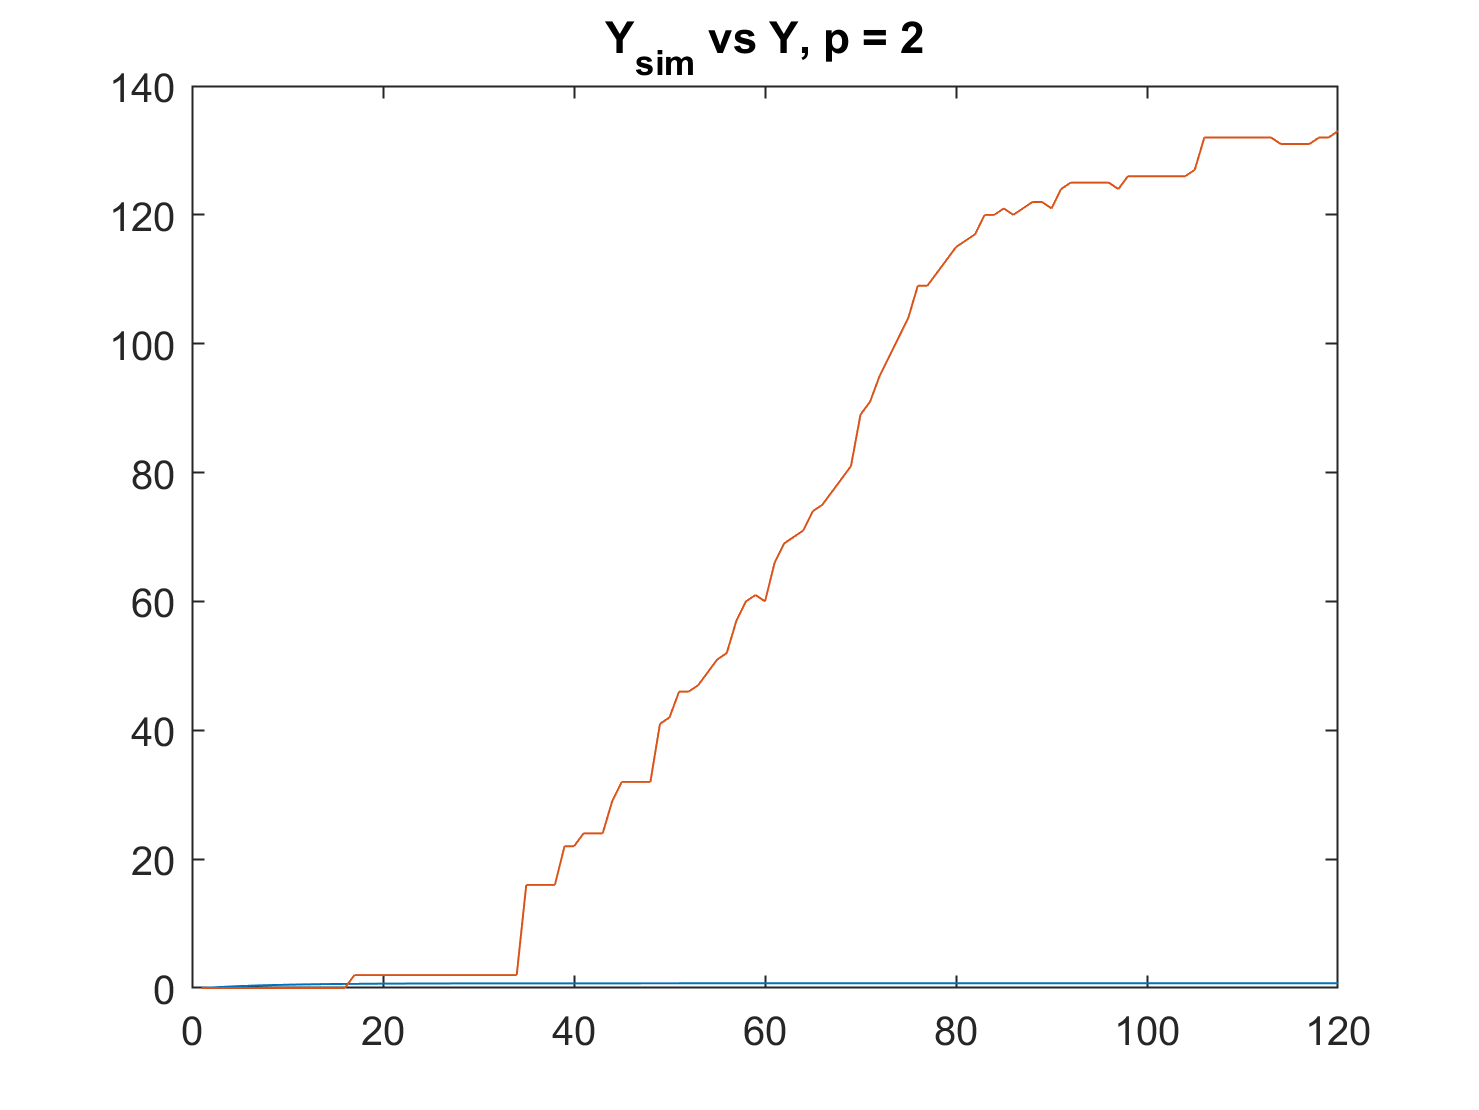

p = 2, predict first day below 5 infections after t0=52 is 53


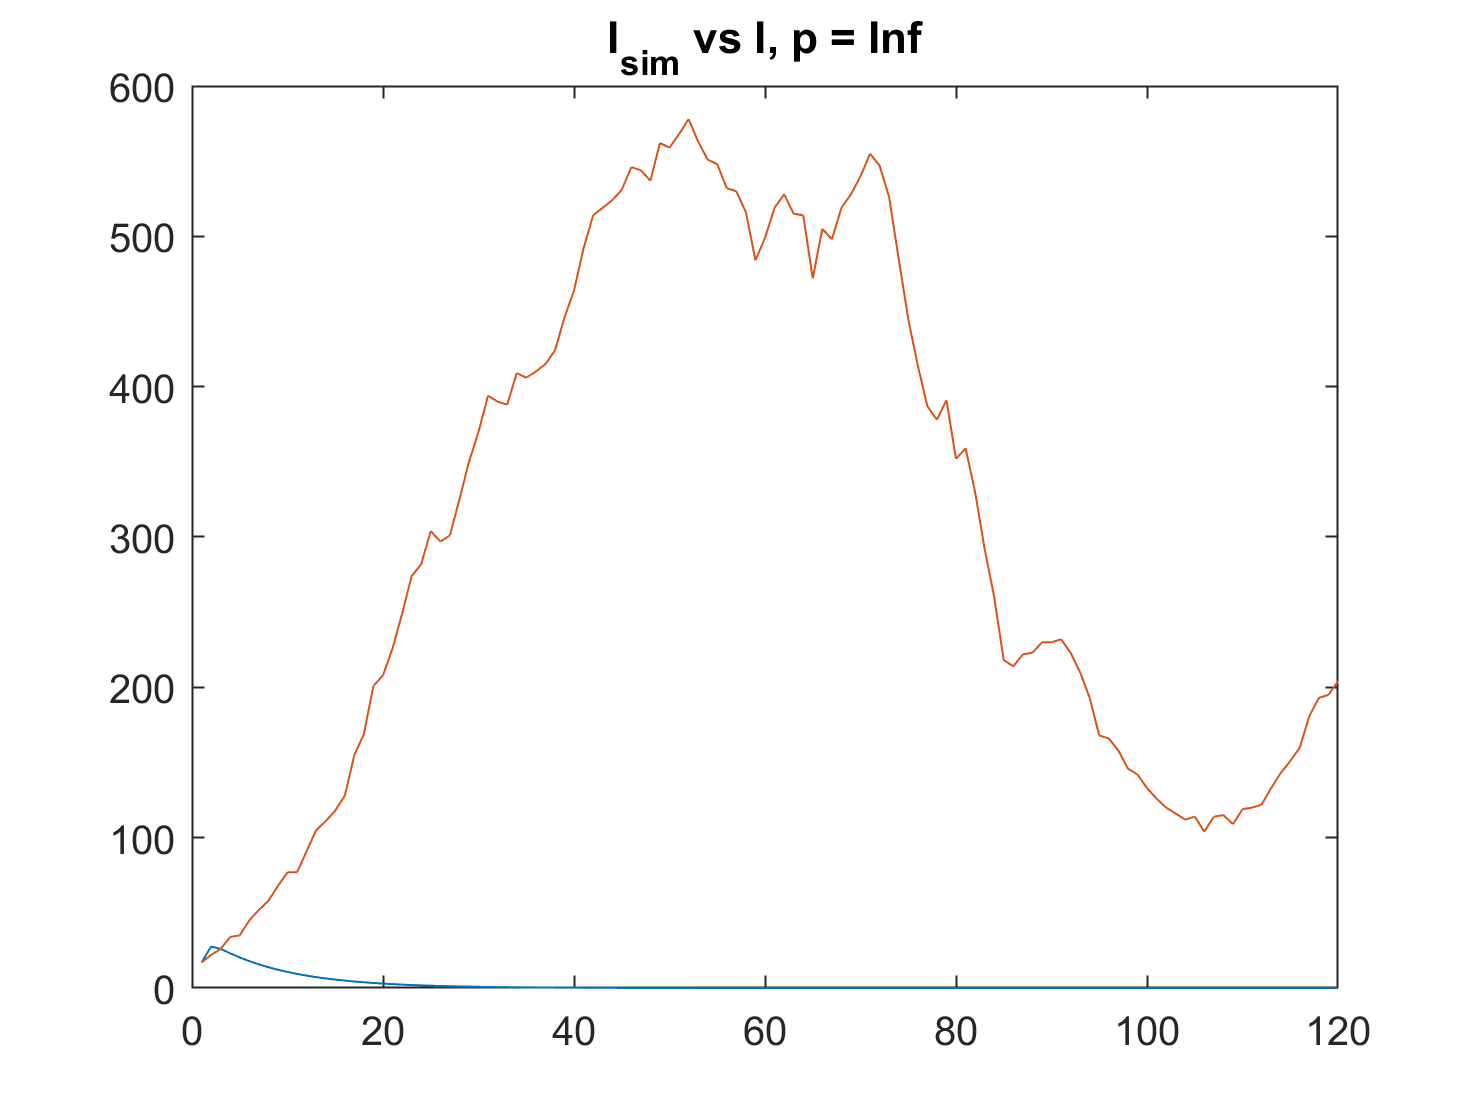

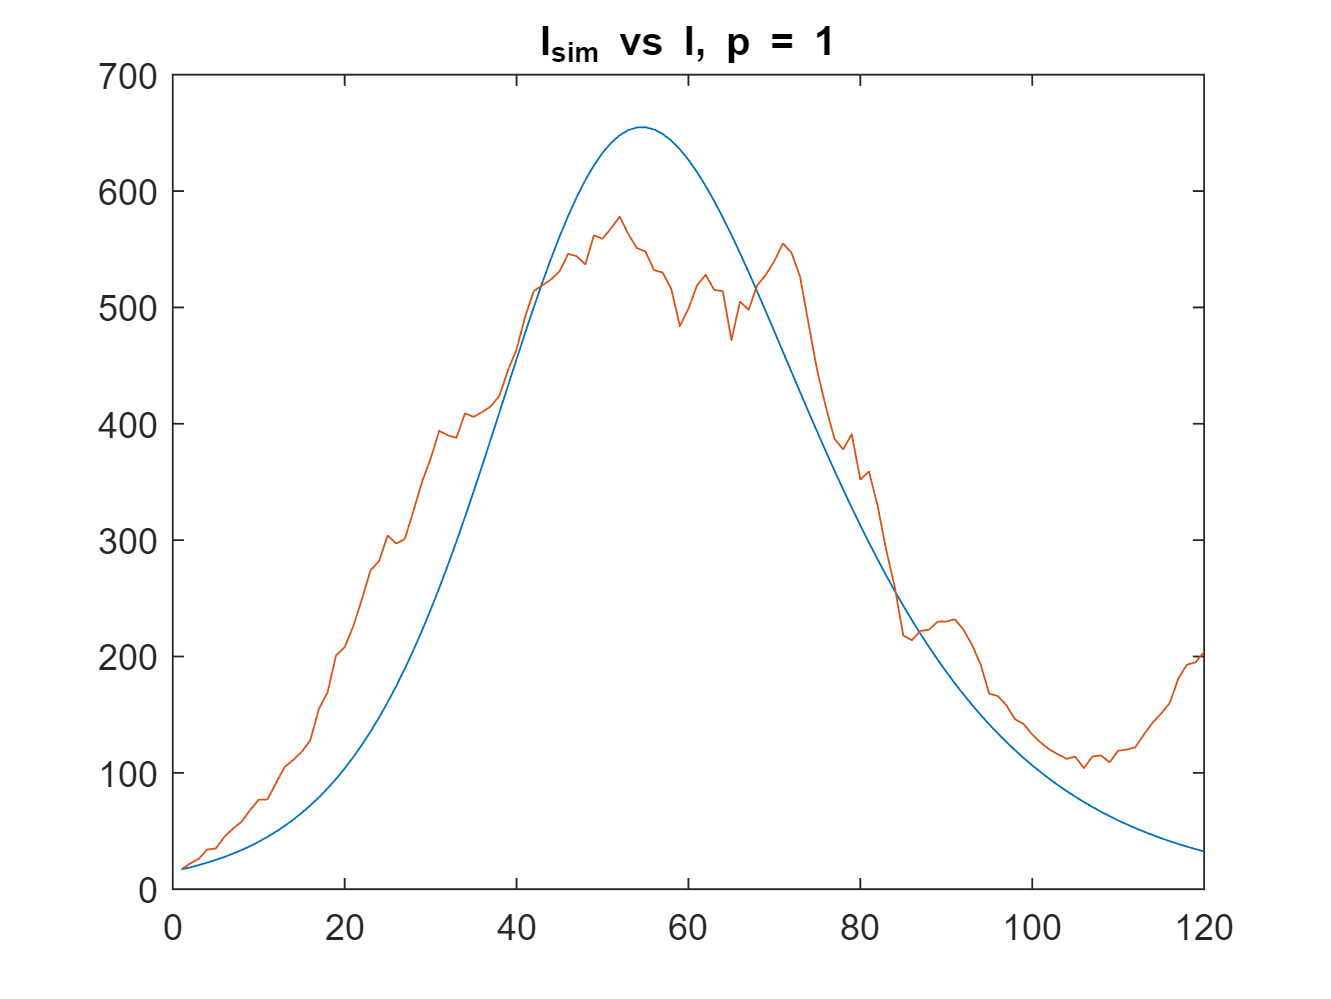

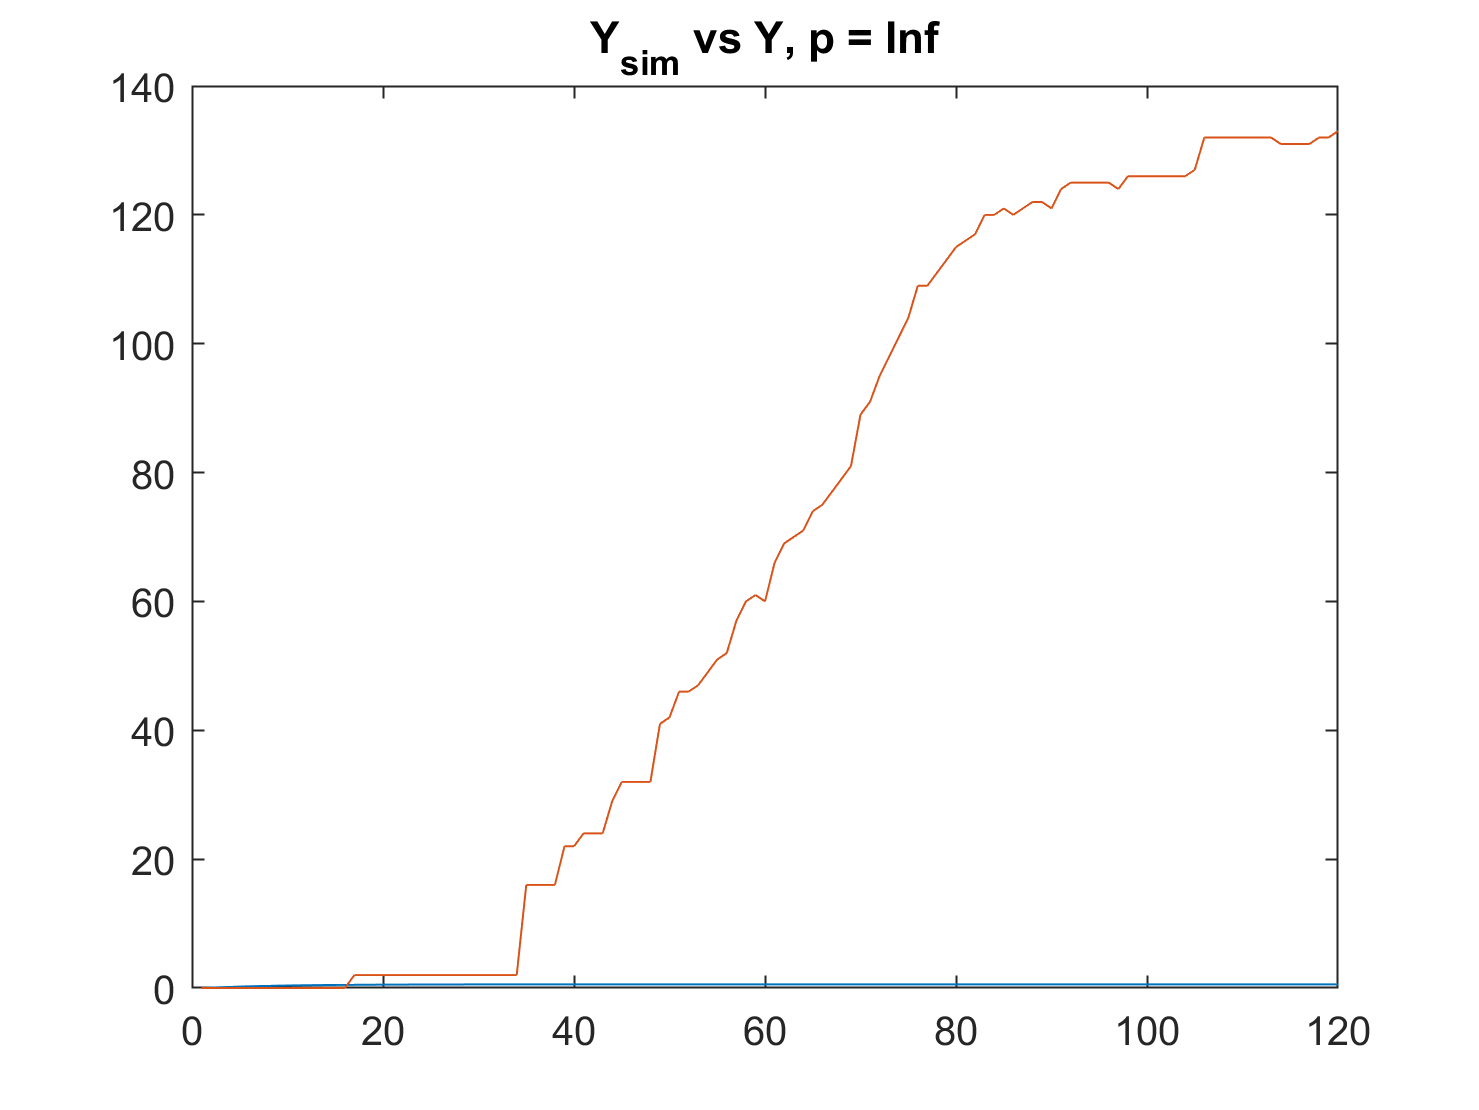

p = Inf, predict first day below 5 infections after t0=52 is 53


%figure
%tl = tiledlayout('flow');

for pInd = 1:pLen
    p = pSet(pInd);
    % Get minimum parameter values
    paramMin = paramMinp3(pInd,:);
    [alphaMin, betaMin, gammaMin, deltaMin, NMin] = paramMin{:};

    % Recalculated because it's not stored previously
    [Ssim, Esim, Isim, Rsim] = SEIR_euler(I0, Tmax, alphaMin, betaMin, deltaMin, NMin);

    % Compare Isim and I
    %nexttile
    figure
    plot(Isim)
    hold on
    plot(I)
    hold off
    %legend(["predicted", "actual"])
    title(['I_{sim} vs I, p = ', num2str(p)])
    saveas(fig, sprintf("VA_SEIR/VA_SEIR_p_%d_I.png",p))

    % Compare Y and Ysim = gamma * Rsim
    %nexttile
    figure
    plot(gammaMin * Rsim)
    hold on
    plot(Y(t0:t0+Tmax))
    hold off
    %legend(["predicted", "actual"])
    title(['Y_{sim} vs Y, p = ', num2str(p)])    
    saveas(fig, sprintf("VA_SEIR/VA_SEIR_p_%d_Y.png",p))

    % Find value of Isim after index t0 below Vmin
    % TODO should I be looking at V instead? I don't know
    % how I would compare that with the output of the model...
    temp_mat = (Isim(t0+1:end)<=Vmin);
    %temp_mat(temp_mat == 0) = NaN;
    [~, min_idx] = max(temp_mat);

    fprintf("p = %d, predict first day below %d infections after t0=%d is %d\n", ...
        p, Vmin, t0, min_idx+t0)
    fprintf("")
end


fprintf("In reality, within the given data, I never goes below %d after t0=%d.\n", Vmin, t0)

In reality, within the given data, I never goes below 5 after t0=52.


## Question 4

[J4, gammas4] = SEIR_euler_allParams(t0, Tmaxnew, I0, Y, I, omega2, pSet);

alphas iterated over: 0.05, 0.06, 0.07, 0.08, 0.09, 0.10, 0.11, 0.12, 0.13, 0.14, 0.15, 0.16, 0.17, 0.18, 0.19, 0.20, 

% Save results (so if I need to restart I don't lose the calculations)
% Commented so that I don't overwrite the results later
%writematrix(J4,"project1_q4_errors_all_p.txt")
%writematrix(gammas4,"project1_q4_gammas_all_p.txt")

% Load matrix from file above
%J4 = readmatrix("project1_q4_errors_all_p.txt");
%J4 = reshape(J4, alphaLen, betaLen, deltaLen, NLen, pLen, [])
%gammas4 = readmatrix("project1_q4_gammas_all_p.txt");
%gammas4 = reshape(gammas4, alphaLen, betaLen, deltaLen, NLen, pLen, [])

J4 = J4(:,:,1,1,1) =

  125.8844  125.6276  125.3689  125.1081  124.8452  125.4603  125.1712  124.8797  124.5852  124.2879  125.1282  124.8109  124.4894  124.1644  123.8259  124.8643  124.5205  124.1720  123.8084  123.4290  124.6506  124.2830  123.9044  123.5029  123.0946  124.4755  124.0859  123.6715  123.2448  122.8084  124.3304  123.9158  123.4737  123.0221  122.5612  124.2085
  126.0164  125.7217  125.4243  125.1237  124.8207  125.5340  125.2016  124.8652  124.5250  124.1810  125.1518  124.7850  124.4132  124.0363  123.6343  124.8429  124.4448  124.0401  123.6077  123.1651  124.5891  124.1619  123.7113  123.2423  122.7638  124.3777  123.9193  123.4291  122.9281  122.4160  124.1994  123.7047  123.1859  122.6550  122.1114  124.0476
  126.1384  125.8084  125.4764  125.1384  124.7983  125.6030  125.2300  124.8522  124.4696  124.0822  125.1741  124.7617  124.3428  123.9129  123.4558  124.8236  124.3747  123.9130  123.4208  122.9182  124.5324  124.0495  123.5312  122.9987  122.4539  124.

%size(J4)
%size(gammas4)

gammas4 = gammas4(:,:,1,1,1) =

    0.0957    0.0944    0.0932    0.0920    0.0908    0.0896    0.0883    0.0870    0.0857    0.0845    0.0848    0.0833    0.0820    0.0807    0.0839    0.0807    0.0792    0.0778    0.0808    0.0795    0.0772    0.0758    0.0785    0.0771    0.0758    0.0743    0.0729    0.0754    0.0739    0.0726    0.0718    0.0742    0.0727    0.0713    0.0698    0.0696
    0.0837    0.0824    0.0811    0.0799    0.0786    0.0780    0.0767    0.0753    0.0740    0.0728    0.0734    0.0720    0.0706    0.0693    0.0719    0.0696    0.0682    0.0668    0.0692    0.0678    0.0664    0.0649    0.0672    0.0657    0.0644    0.0637    0.0657    0.0643    0.0628    0.0614    0.0614    0.0633    0.0618    0.0603    0.0589    0.0594
    0.0751    0.0738    0.0726    0.0712    0.0700    0.0697    0.0683    0.0670    0.0657    0.0645    0.0654    0.0639    0.0625    0.0646    0.0634    0.0617    0.0603    0.0622    0.0608    0.0595    0.0587    0.0572    0.0590    0.0576    0.

[~, ~, ~, ~, paramMinp4] = SEIR_euler_minParams(omega2, pSet, J4, gammas4, Nmax)

ans =     16    36     5     9     3


%figure

ans =     16    36     5     9     3


%tl = tiledlayout('flow');


For p = 1, the parameters which reduce the error are
alpha = 0.050, beta = 0.020, gamma = 0.070, delta = 1.500, N = 23684.2
(R0 = 0.400, Nfrac = 0.100)
with an error of 8773.443959

For p = 2, the parameters which reduce the error are
alpha = 0.050, beta = 0.020, gamma = 0.220, delta = 1.500, N = 23684.2
(R0 = 0.400, Nfrac = 0.100)
with an error of 1716.552015

For p = Inf, the parameters which reduce the error are
alpha = 0.050, beta = 0.020, gamma = 0.350, delta = 1.500, N = 23684.2
(R0 = 0.400, Nfrac = 0.100)
with an error of 491.943885



paramMinp4 = 3×5 cell array
    {[0.0500]}    {[0.0200]}    {[0.0701]}    {[1.5000]}    {[2.3684e+04]}
    {[0.0500]}    {[0.0200]}    {[0.2199]}    {[1.5000]}    {[2.3684e+04]}
    {[0.0500]}    {[0.0200]}    {[0.3502]}    {[1.5000]}    {[2.3684e+04]}


for pInd = 1:pLen
    p = pSet(pInd);
    % Get minimum parameter values
    paramMin = paramMinp4(pInd,:);
    [alphaMin, betaMin, gammaMin, deltaMin, NMin] = paramMin{:};

    % Recalculated because it's not stored previously
    [Ssim, Esim, Isim, Rsim] = SEIR_euler(I0, Tmax * 2, alphaMin, betaMin, deltaMin, NMin);

    % Compare Isim and I
    %nexttile
    figure
    plot(Isim)
    hold on
    plot(I)
    hold off
    %legend(["predicted", "actual"])
    title(['I_{sim} vs I, p = ', num2str(p)])
    saveas(fig, sprintf("VA_SEIR/Prediction/VA_SEIR_Prediction_p_%d_I.png",p))

    % Compare Y and Ysim = gamma * Rsim
    %nexttile
    figure
    plot(gammaMin * Rsim)
    hold on
    plot(Y(t0:t0+Tmax))
    hold off
    %legend(["predicted", "actual"])
    title(['Y_{sim} vs Y, p = ', num2str(p)])    
    saveas(fig, sprintf("VA_SEIR/Prediction/VA_SEIR_Prediction_p_%d_Y.png",p))

    % Find value of Isim after index t0 below Vmin
    % TODO should I be looking at V instead? I don't know
    % how I would compare that with the output of the model...
    temp_mat = (Isim(t0+1:end)<=Vmin);
    %temp_mat(temp_mat == 0) = NaN;
    [~, min_idx] = max(temp_mat);

    fprintf("p = %d, predict first day below %d infections after t0=%d is %d\n", ...
        p, Vmin, t0, min_idx+t0)
    fprintf("")
end

fprintf("In reality, within the given data, I never goes below %d after t0=%d.\n", Vmin, t0)

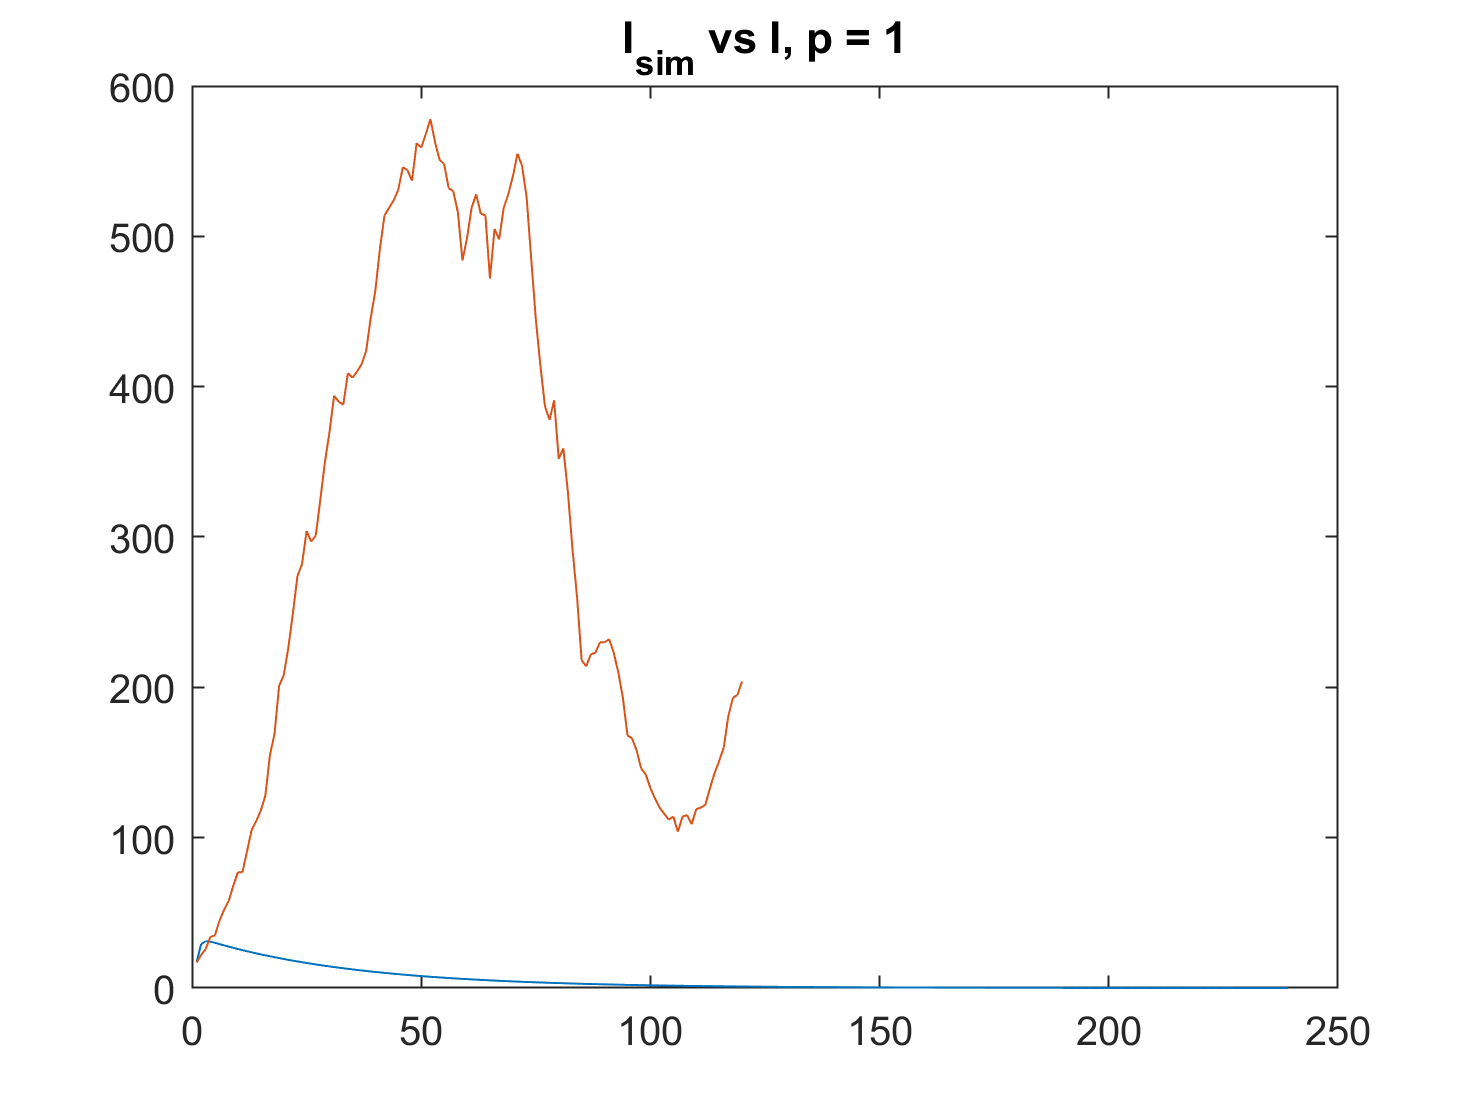

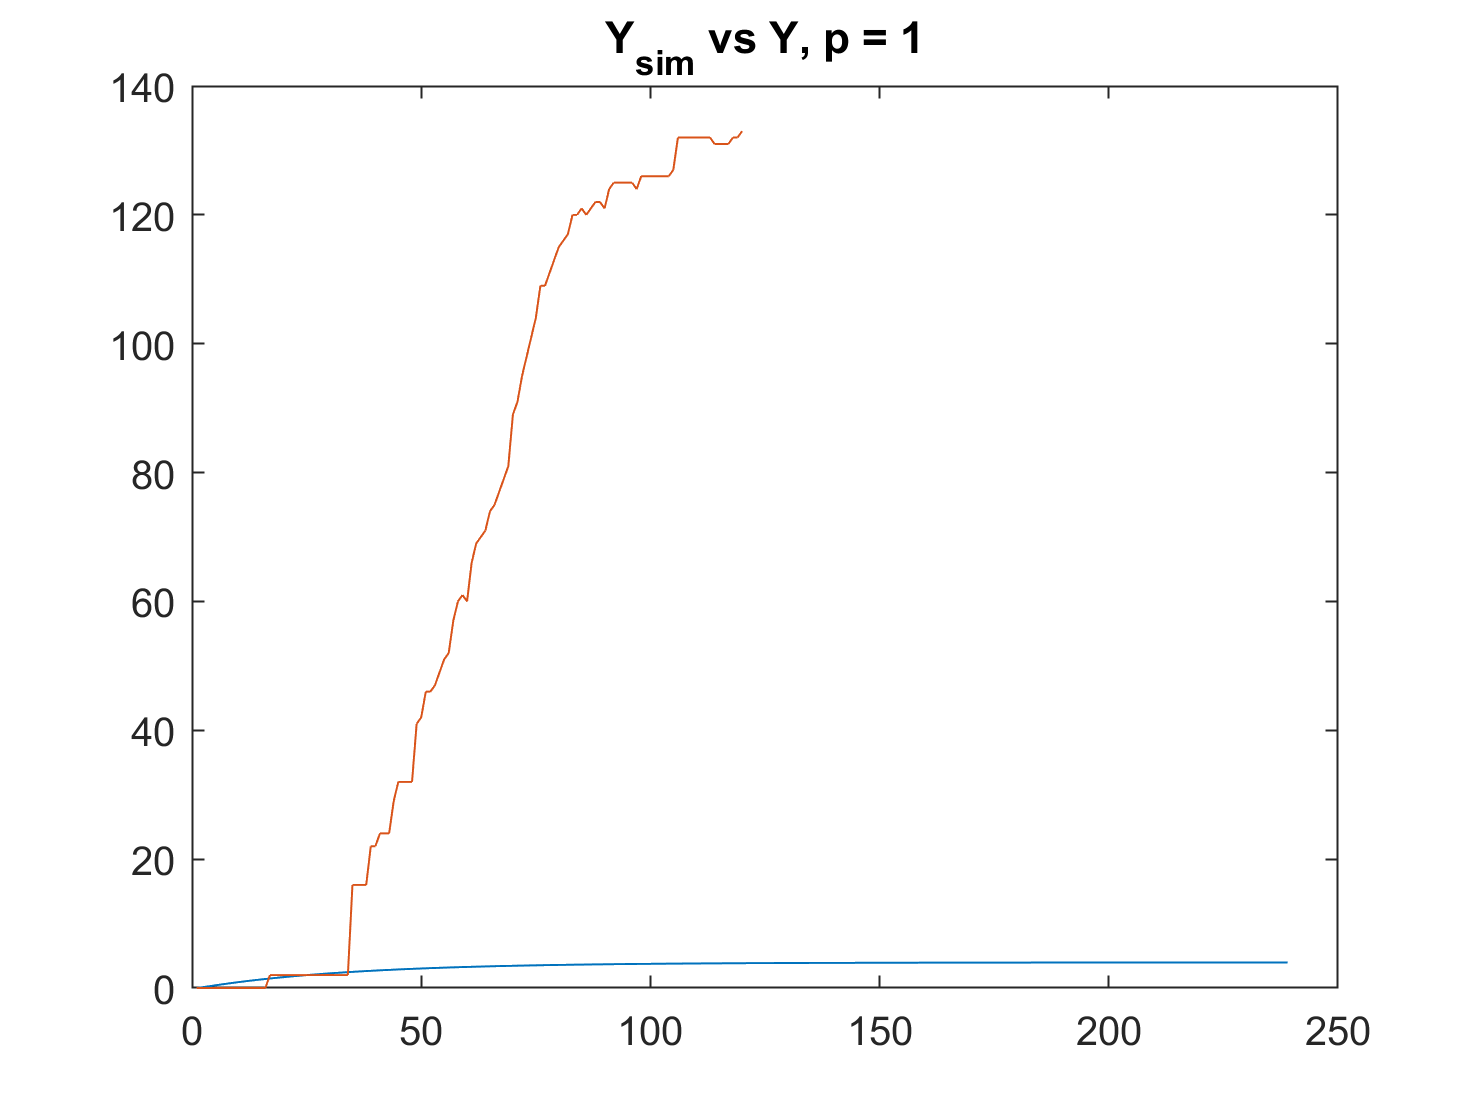

p = 1, predict first day below 5 infections after t0=52 is 66


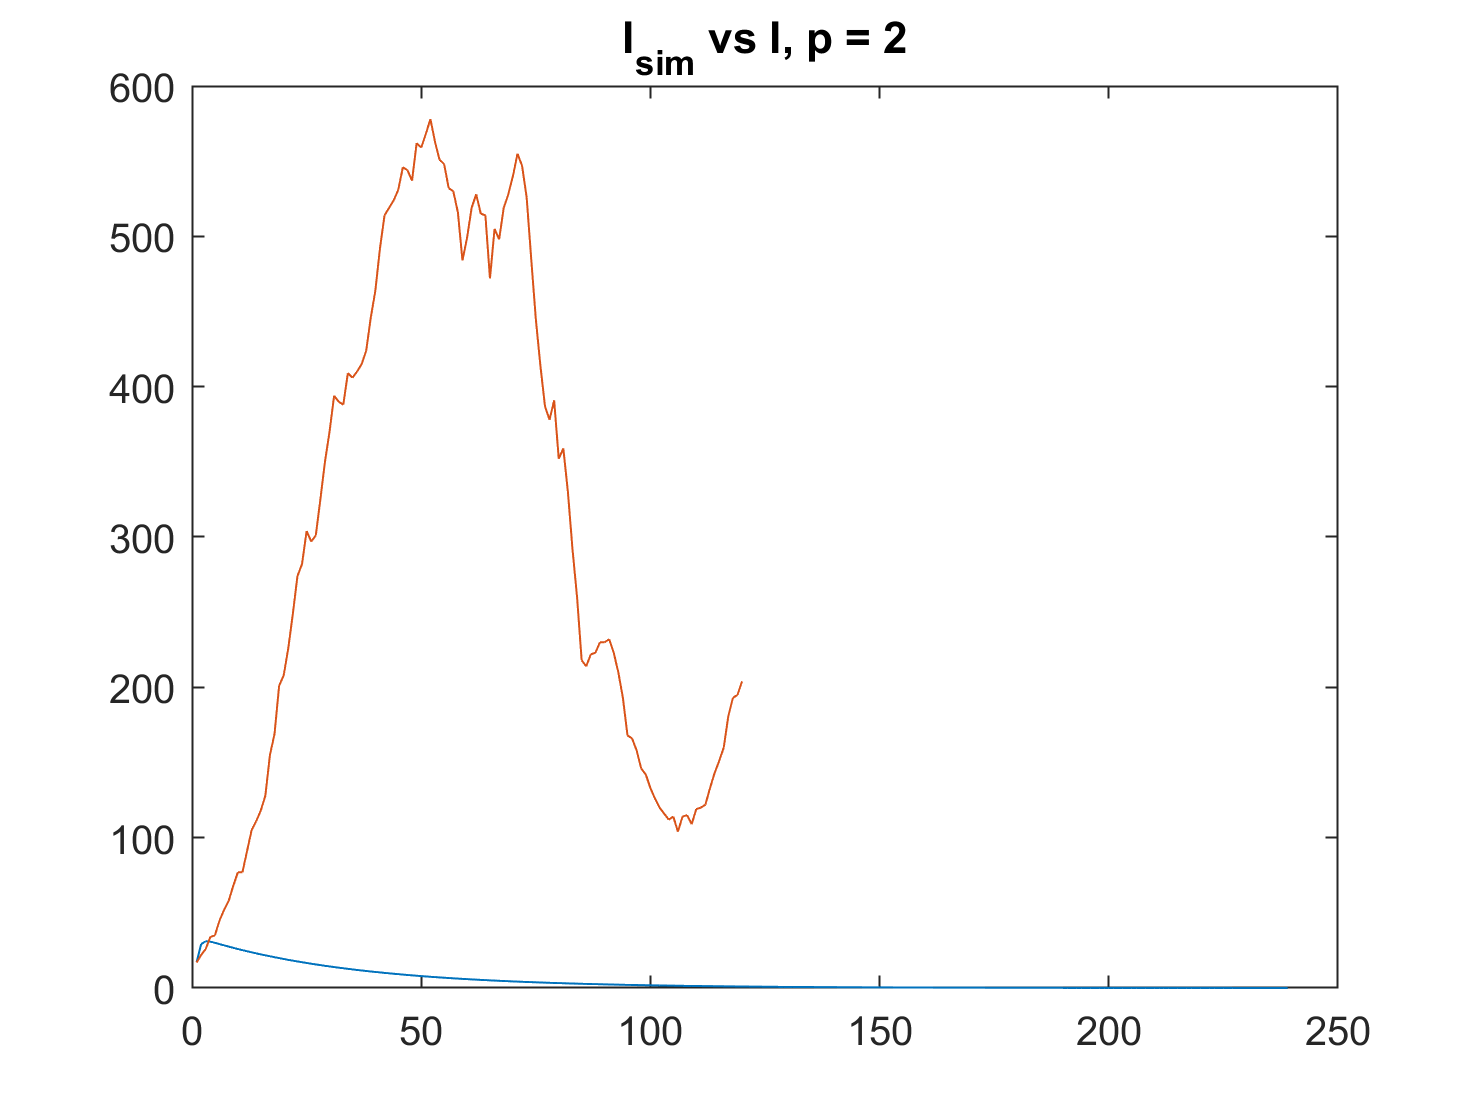

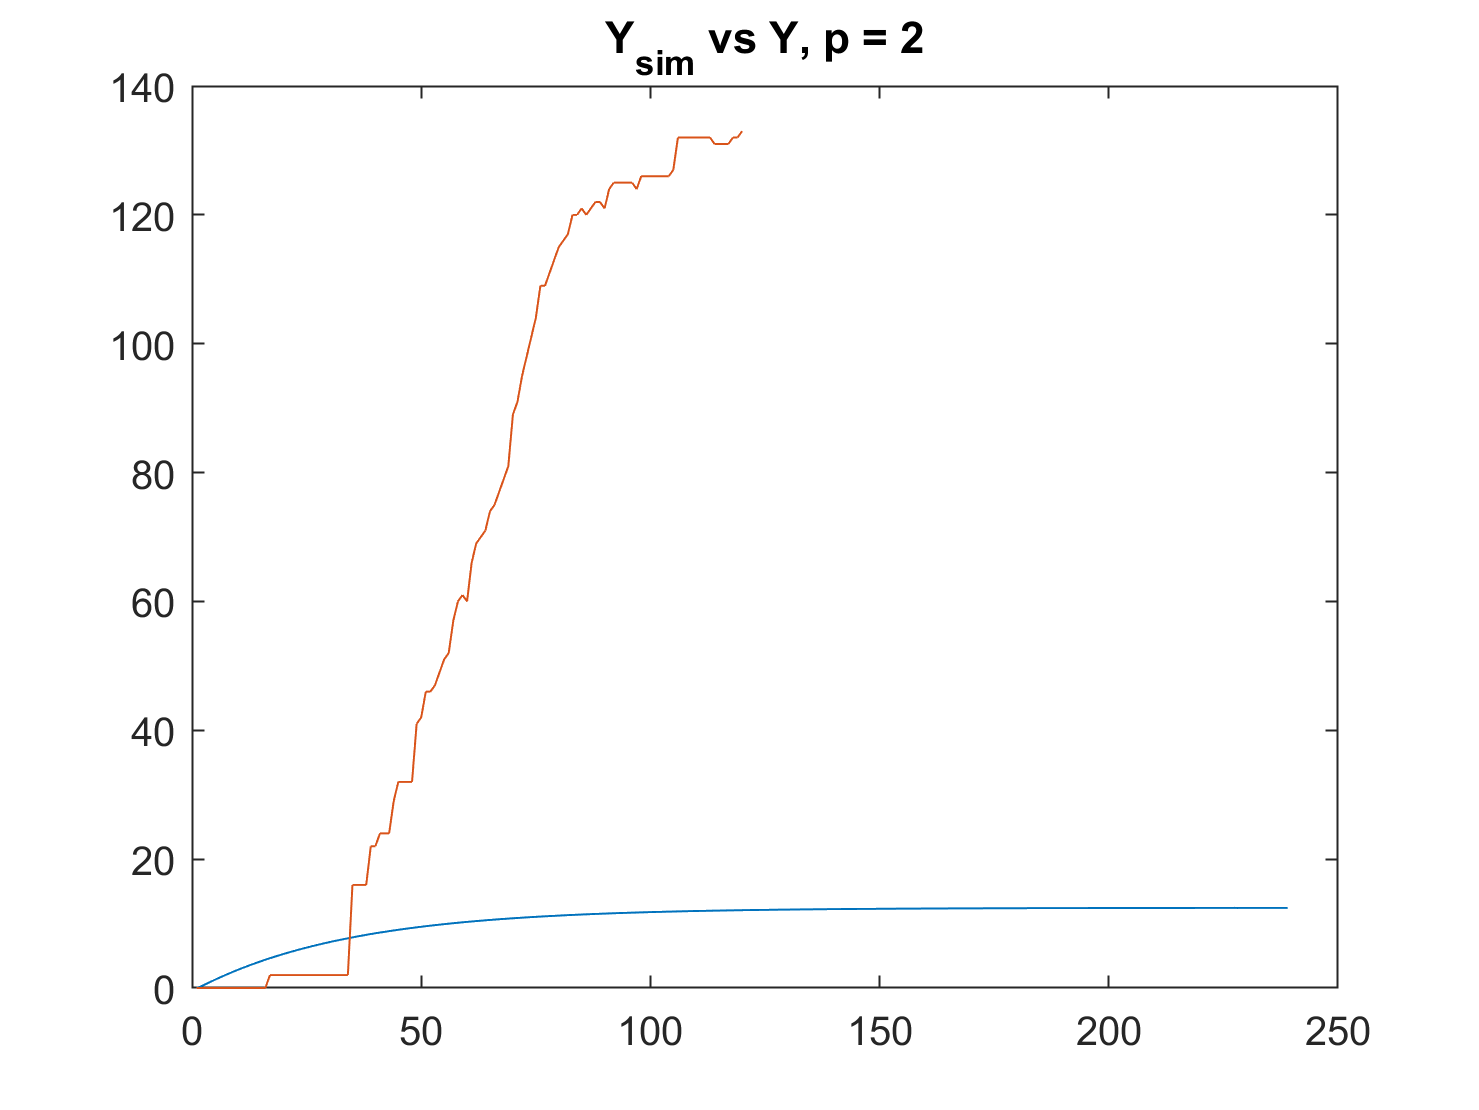

p = 2, predict first day below 5 infections after t0=52 is 66


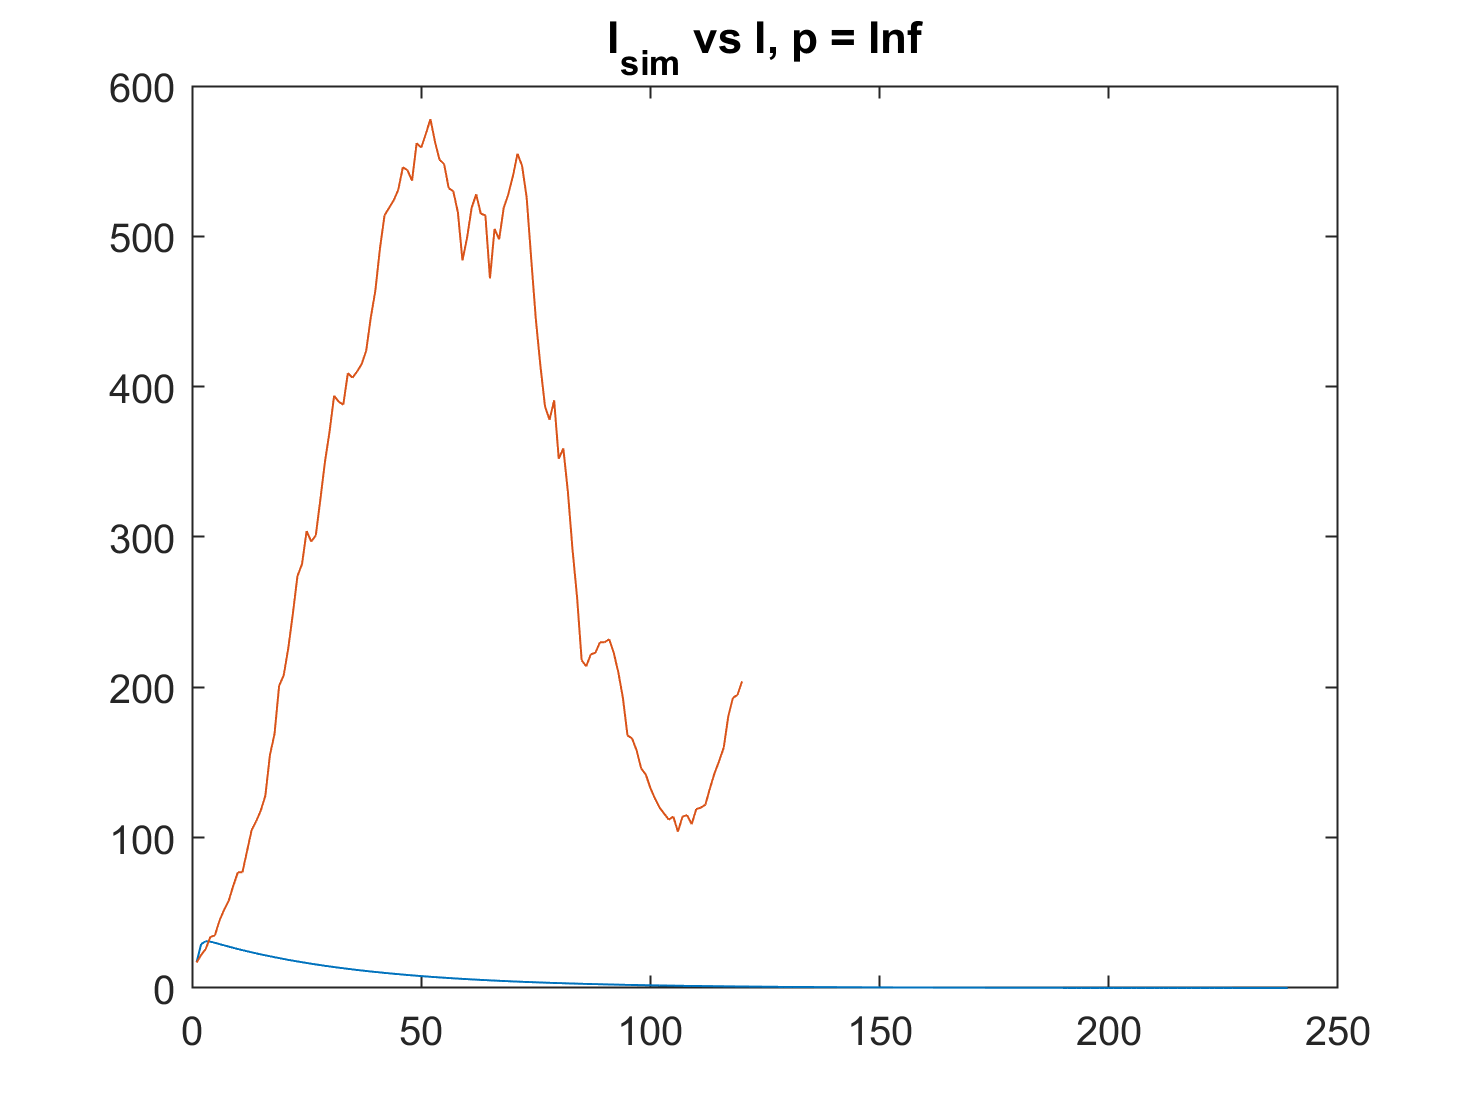

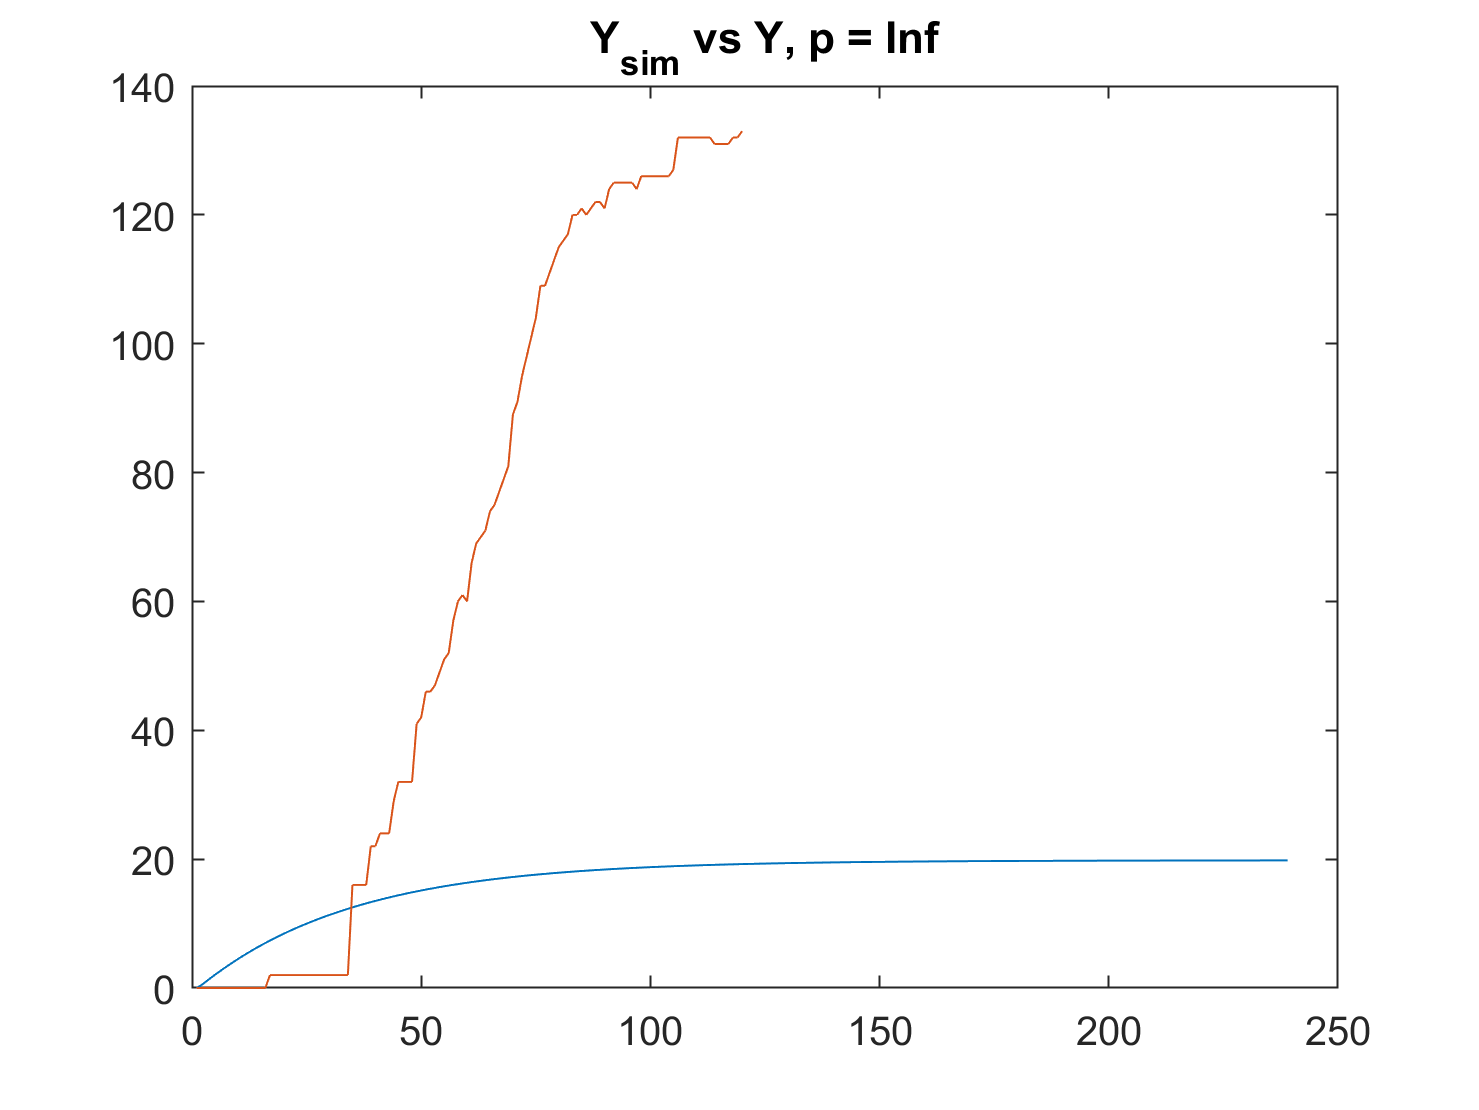

p = Inf, predict first day below 5 infections after t0=52 is 66


In reality, within the given data, I never goes below 5 after t0=52.
